Target group: M2SAAS - Universite Evry Paris Saclay

**Flight Modeling Lab Final Report**

Prepared by: Melkamu Amare ==> ID: 20245847

                  Abel Yehuala ==> ID: 20245853

M2SAAS - 2024

Submitted to: Mr. Amayas Benoudiba

Universite Evry Paris-Saclay

# Objectives

Objectives of this lab:

- Familiarization with modeling and simulation with Matlab/Simulink — Linear control systems : linearization and stabilization 

- Design an autopilot for a drone using the ”exact linearization” approach and other nonlinear approaches. 

- Stabilization and trajectory tracking control. Consider a drone (rocket) having airships at angles in two perpendicular directions. 

# Introduction theory about the plant

The nonlinear model of the drone is expressed as a state representation form with 12 variables that correspond to positions, velocities, angular positions and angular velocities, which will be controlled via 4 control inputs. The 4 controls are respectively : the thrust T, the 2 angles of rotation α and β, the roll control input M*ψ. 

By choosing the following state variables :

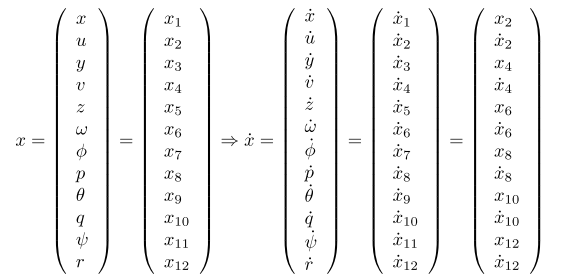

Then we obtain the state representation of our system, we replace these state variables in the equations of motion we get :

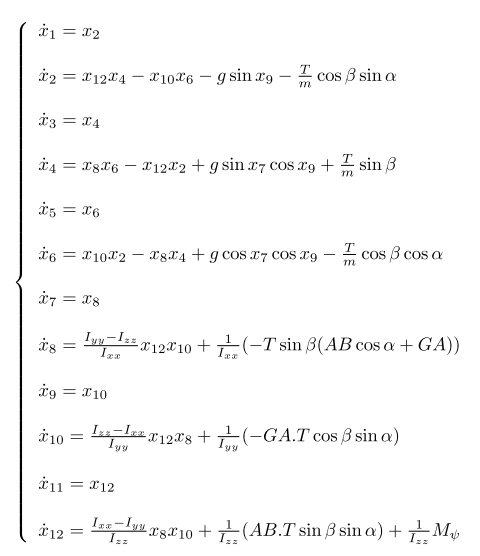

From the equations(1), we define the control input vector u by :

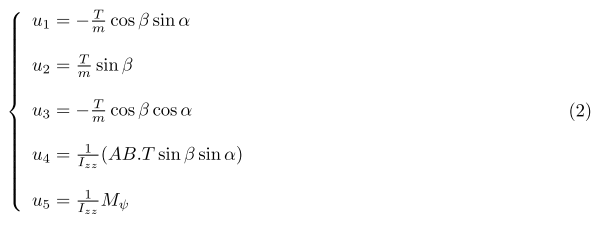

For small rotation angles :

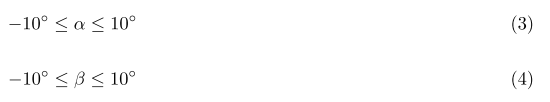

It is possible to use the approximations :

The, the control inputs ui, i = 1, ..., 5 are simplified as follows :

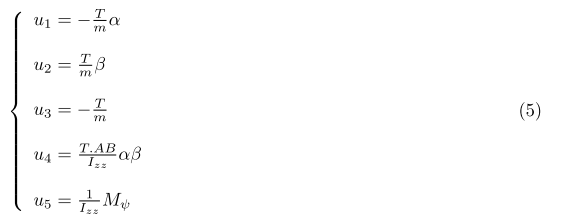

which gives the following state space representation :

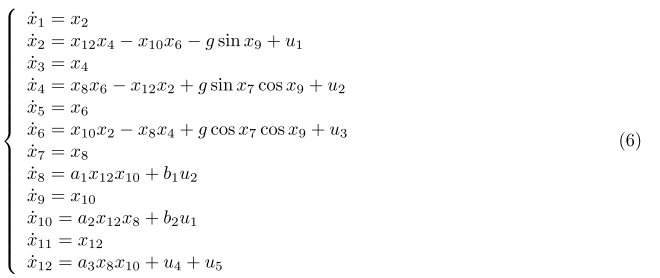

with

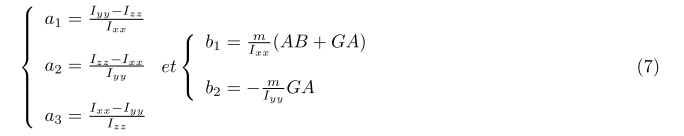

# Questions

### a. Analyze the provided Simulink model 

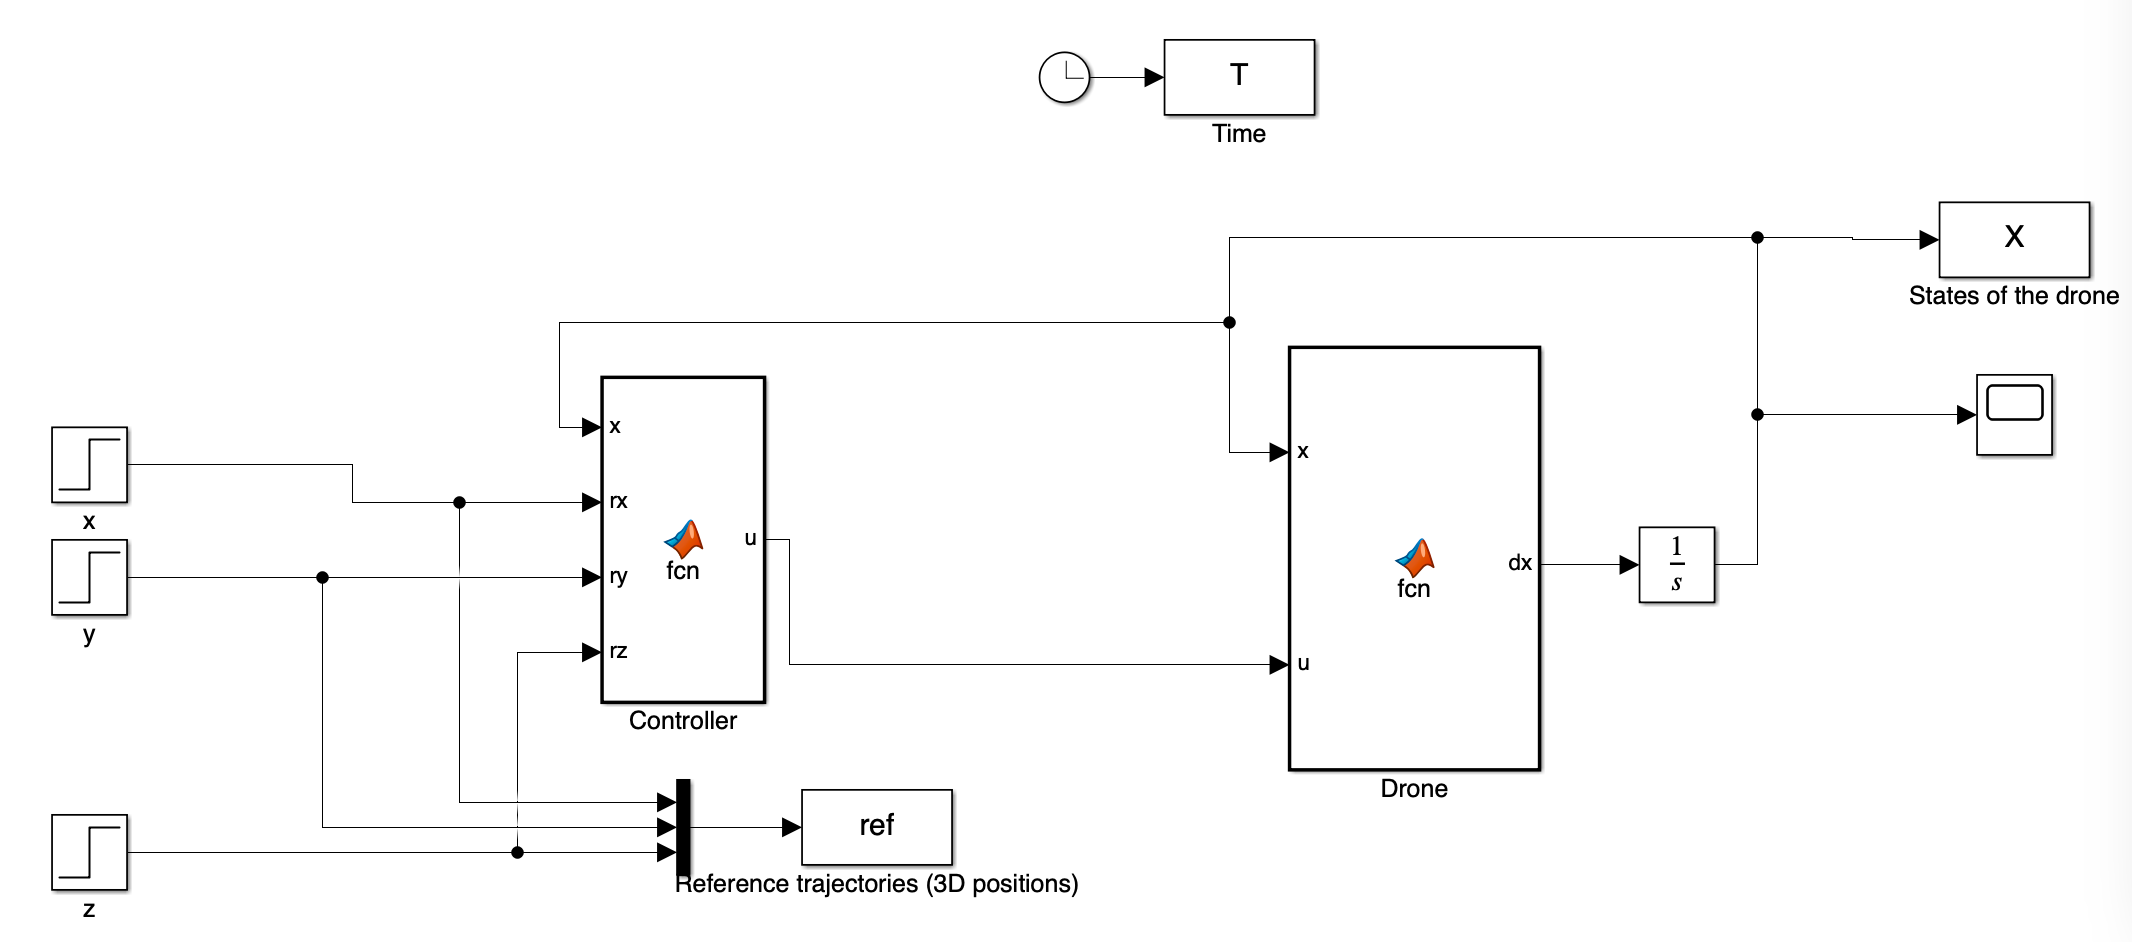

The given Simulink model: 

**Components of the Simulink model**: reference input, controller, plant(Drone), 

The provided drone model is a 6-degree-of-freedom (6DoF) model featuring 12 states, where each pair of states represents a two-block derivative of a single degree of freedom. The state space vector, denoted as X, captures the essential states of the Unmanned Aerial Vehicle (UAV), and it can be further articulated in terms of linear and angular accelerations.

The control input of the quadcopter model, represented by u, consists of four components which are u1 = total thrust input, u2 = roll control input, u3 = pitch control input, and u4 = yaw control input.

The model also exhibits strong non-linearity due to the interdependence among states, involving functions such as "sin" and "cos." The nonlinear UAV model can be expressed as a set of differential equations that govern the dynamics of the system.

### b. Compute the equilibrium points of the system and show that the origin is an equilibrium point.

to get the equilibrium point lets start from 


$$\dot{x}  = 0$$


$
0 = x_2 \\
0 = x_{12}x_4 - x_{10}x_6 - g \sin x_9 + u_1 \\
0 = x_4 \\
0 = x_8x_6 - x_{12}x_2 + g \sin x_7 \cos x_9 + u_2 \\
0 = x_6 \\
0 = x_{10}x_2 - x_8x_4 + g \cos x_7 \cos x_9 + u_3 \\
0 = x_8 \\
0 = a_1 x_{12}x_{10} + b_1u_2 \\
0 = x_{10} \\
0 = a_2x_{12}x_8 + b_2u_1 \\
0 = x_{12} \\
0 = a_3x_8x_{10} + u_4 + u_5$         ==>              $
u_1 = g \sin x_9, \\
u_2 = -g \sin x_7 \cos x_9, \\
u_3 = -g \cos x_7 \cos x_9, \\
b_1 u_2 = 0, \\
b_2 u_1 = 0, \\
u_4 + u_5 = 0.$

Since g, b1 and b2 are diffrent from zero, u1 and u2 are zero at equilibrium point. 

Therefore,  $g \sin x_9 = 0, \\
g \sin x_7 \cos x_9 = 0, \\
g \cos x_7 \cos x_9 = 0, \\$    ==> $\sin x_9 = 0, \text{iff} , x_9 = k\pi  , \text{where}, k = 0, 1, 2, ...\\
\sin x_7 \cos x_9 = 0, \text{iff} , x_9 = (2k+1)\pi /2 (or)  x_7 = k\pi  , \text{where}, k = 0, 1, 2, ...\\
\cos x_7 \cos x_9 = 0, \text{iff} , x_7 = x_9 = (2k+1)\pi /2,  \text{where}, k = 0, 1, 2, ...\\$

From this condition, we can say that **u_3** must be different from zero and **u_4 = -u_5** to make our plant stable at the origin. For **u_3, **if **x_7 and x_9** are taken to be zero, there **cos** will be 1.

So, if the above condition is satisfied, the equilibrium point will be


$$[x, u] = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, u_3, u_4, -u_5]$$


# 1. Linear longitudinal and lateral control

After decoupling (under some conditions which will be explained), the decoupled, lateral and longitudinal motions of the drone are given by the dynamical models:

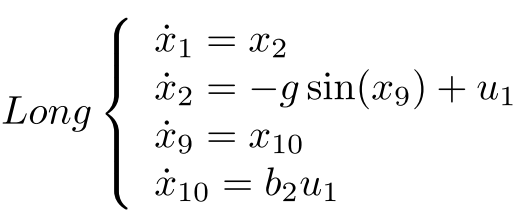

where x1 et x2 represent the position and the velocity with respect to the x−axis and x9 and x10 the roll angle and its rate. u1 is the trust generated by the wings with respect to x−axis.

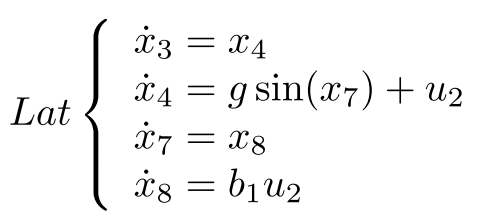

where x_3 and x_4 represent the position and the velocity with respect to the y−axis and x_7 and x_8 the pitch angle and its rate. u_2 is the trust generated by the wings with respect to y−axis.

#### **1. Compute the linearized models around the origin of each model ?**

Longitudinal linearization at the origin

$

\[
\frac{\partial \dot{x_1}}{\partial x_1} = 0, \quad
\frac{\partial \dot{x_1}}{\partial x_2} = 1, \quad
\frac{\partial \dot{x_1}}{\partial x_9} = 0, \quad
\frac{\partial \dot{x_1}}{\partial x_{10}} = 0,
\]

\[
\frac{\partial\dot{x_2}}{\partial{x_1}} = 0, \quad
\frac{\partial\dot{x_2}}{\partial{x_2}}= 0, \quad
\frac{\partial\dot{x_2}}{\partial{x_9}}|_{x_9=0} = -g, \quad
\frac{\partial\dot{x_2}}{\partial{x_{10}}}  = 0,
\]

\[
\frac{\partial\dot{x_9}}{\partial{x_1}} = 0, \quad
\frac{\partial\dot{x_9}}{\partial{x_2}} = 0, \quad
\frac{\partial\dot{x_9}}{\partial{x_9}} = 0, \quad
\frac{\partial\dot{x_9}}{\partial{x_{10}}} = 1
\]

\[
\frac{\partial\dot{x_{10}}}{\partial{x_1}} = 0, \quad
\frac{\partial\dot{x_{10}}}{\partial{x_2}} = 0, \quad
\frac{\partial\dot{x_{10}}}{\partial{x_9}} = 0, \quad
\frac{\partial\dot{x_{10}}}{\partial{x_{10}}} = 0
\]
$  A = $\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & -g & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$; B =    $\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\textrm{b2}
\end{array}\right\rbrack$

Lateral linearization at the origin

$

\[
\frac{\partial \dot{x_3}}{\partial x_3} = 0, \quad
\frac{\partial \dot{x_3}}{\partial x_4} = 1, \quad
\frac{\partial \dot{x_3}}{\partial x_7} = 0, \quad
\frac{\partial \dot{x_3}}{\partial x_8} = 0,
\]

\[
\frac{\partial\dot{x_4}}{\partial{x_3}} = 0, \quad
\frac{\partial\dot{x_4}}{\partial{x_4}}= 0, \quad
\frac{\partial\dot{x_4}}{\partial{x_9}}|_{x_7=0} = g, \quad
\frac{\partial\dot{x_4}}{\partial{x_8}}  = 0,
\]

\[
\frac{\partial\dot{x_7}}{\partial{x_3}} = 0, \quad
\frac{\partial\dot{x_7}}{\partial{x_4}} = 0, \quad
\frac{\partial\dot{x_7}}{\partial{x_7}} = 0, \quad
\frac{\partial\dot{x_7}}{\partial{x_8}} = 1
\]

\[
\frac{\partial\dot{x_8}}{\partial{x_3}} = 0, \quad
\frac{\partial\dot{x_8}}{\partial{x_4}} = 0, \quad
\frac{\partial\dot{x_8}}{\partial{x_7}} = 0, \quad
\frac{\partial\dot{x_8}}{\partial{x_8}} = 0
\]
$  A = $\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & g & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$; B =    $\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\textrm{b1}
\end{array}\right\rbrack$

#### 2. For each motion, compute a linear controller by state feedback control and pole placement technique.

**State feedback - pole placement** is a control design technique used to place the poles of a closed-loop system at desired locations in the complex plane by designing a suitable state feedback controller. The goal is to achieve desired system dynamics, such as stability, performance, and responsiveness, by modifying the eigenvalues of the closed-loop system matrix.

**Objective of pole placement:**

By choosing K, the designer can move the eigenvalues of (A−BK) (the closed-loop poles) to specific locations that correspond to desired dynamics, such as:

- Faster response (poles with larger negative real parts in the left-half plane).

- Oscillatory behavior (complex conjugate poles with controlled damping and frequency).

- Reduced overshoot and settling time.

From state feedback, we have u = -Kx(t) + r(t)


$$\dot{x} = Ax + Bu ; \ where \ ; u = -Kx+v \\
\dot{x} = (A-BK)x + Bv \\$$


We can insure the referencer tracking  


$$
\dot{\mathbf{x}} = Ax + Bu,  <-->
y = Cx <-->
u = -Kx +  v,

\[
\dot{x} = (A - BK)x + Bv.
<> \dot{x} = 0\ ==>
\text{At steady state}:
 \]

\[
0 = (A - BK)x + Bv,
\text{ which leads to}:
x = -(A - BK)^{-1} Bv.
\]

From the output equation:
\[
y = Cx,
\text{substitute for} \ x: >
y = C \left[ -(A - BK)^{-1} B \right]v.
\]

To ensure reference tracking (\(y = r\)):
\[
r = \left[ -C(A - BK)^{-1} B \right] v.
\]


Solving for v:
\[
v = -\left[C(A - BK)^{-1} B\right]^{-1}r .
\]

If the matrix is not invertible, we use the pseudo-inverse:
\[
v = -\text{pinv}\left(C(A - BK)^{-1} B\right)r .
\]$$


Now, we can find the value of K using Ackerman's function in MATLAB by setting a desired pole p in the LHS region for stability

clc;
% longitudinal state feedback
g = 9.81; b1 = 1; b2 = 1;
p = [-6, -8, -5, -4]; % desired poles
A = [0 1 0 0; 0 0 -g 0; 0 0 0 1; 0 0 0 0];
B =[0; 1; 0; b2]; 
K1 = acker(A, B, p)

K1 =   -97.8593  -72.5790  291.8593   95.5790


size(K1)

ans =      1     4


C = eye(4);
A1 = inv(A - (B*K1));
V_mat1 = -pinv(C*A1*B);



% lateral state feedback
A2 = [0 1 0 0; 0 0 g 0; 0 0 0 1; 0 0 0 0]; 
B2 =[0; 1; 0; b1]; 
K2 = acker(A2, B2, p)

K2 =    97.8593   72.5790   96.1407  -49.5790


C2 = eye(4);
D = 0;
A21 = inv(A2 - (B2*K2));
V_mat2 = -pinv(C2*A21*B2);


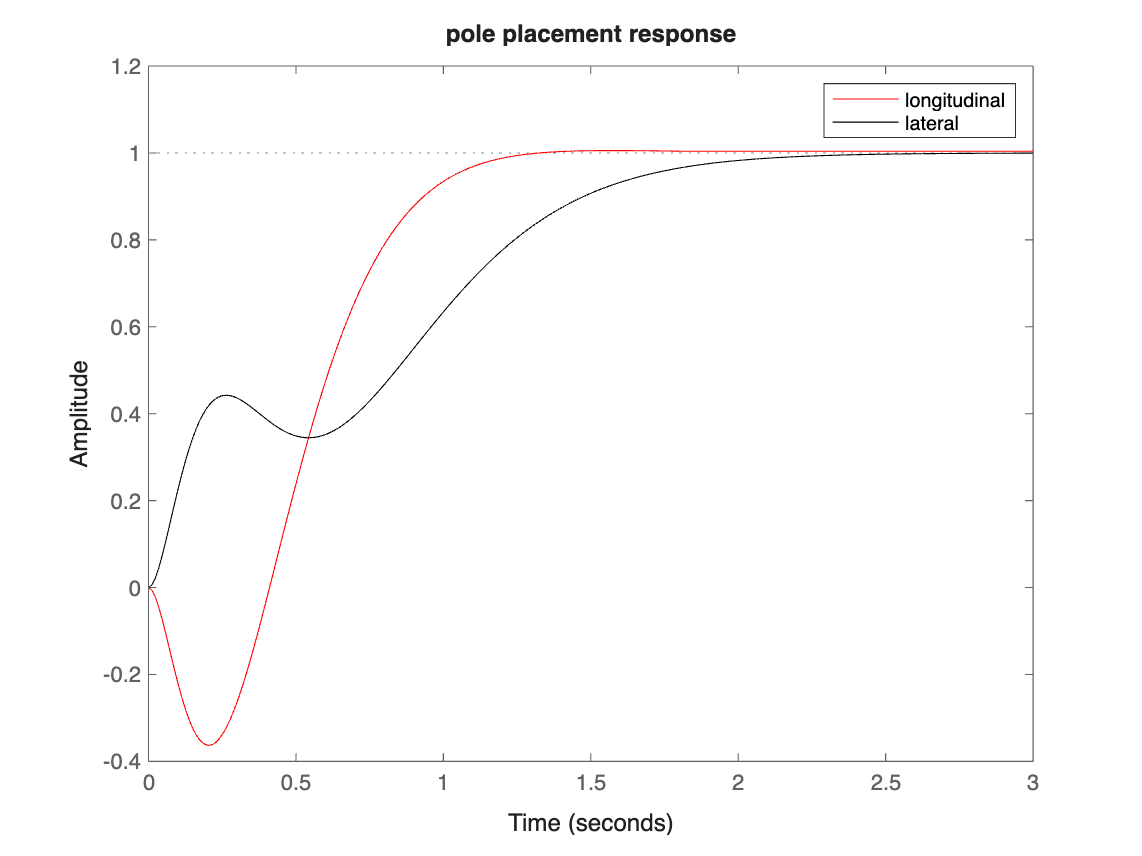


% State-Space for Longitudinal with pole placement
lon_pole = ss(A - B*K1, B, C, D); 

% Step Responses for Longitudinal Models figure;
step(lon_pole(1)/dcgain(lon_pole(1)), 'r-'); 

hold on;

% State-Space for Longitudinal with pole placement
lat_pole = ss(A2 - B2*K2, B2, C2, D); 

% Step Responses for Longitudinal Models figure;
step(lat_pole(1)/dcgain(lat_pole(1)), 'k-'); 
hold off;

legend('longitudinal', 'lateral');
title('pole placement response');

As we can see the result, the step response of the pole placement method is settled in 1 second for longitudinal and 2 seconds for lateral motion. This is a short period of time for non-critical systems to be stable, so the controller is efficient for constant inputs in the linear state space model. Lets apply it to the nonlinear plant.

#### 3. Apply the proposed control techniques directly on the nonlinear model. Discuss the results.

Since the longitudinal and lateral motions are controlled by u_1 and u_2 respectively, we only play with the two inputs to control the motion.

To apply the linearized controller in to the non-linear plant, lets add the following code snippet into the original controller code (given with the model).

xlong = [x(1); x(2); x(9); x(10)];

u(1) = -K*xlong+V_mat1(1)*rx; % To be completed;


xlat = [x(3); x(4); x(7); x(8)];

u(2) = -K2*xlat + V_mat2(1)*ry; % To be completed;

K1 =    -3.4641   -6.4337   41.6177   16.4490


S = 1.0e+04 *

    0.0669    0.0441   -0.1709   -0.0545
    0.0441    0.0645   -0.2630   -0.0838
   -0.1709   -0.2630    1.2320    0.3879
   -0.0545   -0.0838    0.3879    0.1331


P =   -1.0005 + 0.0000i
  -2.8452 + 1.4566i
  -2.8452 - 1.4566i
  -3.3245 + 0.0000i


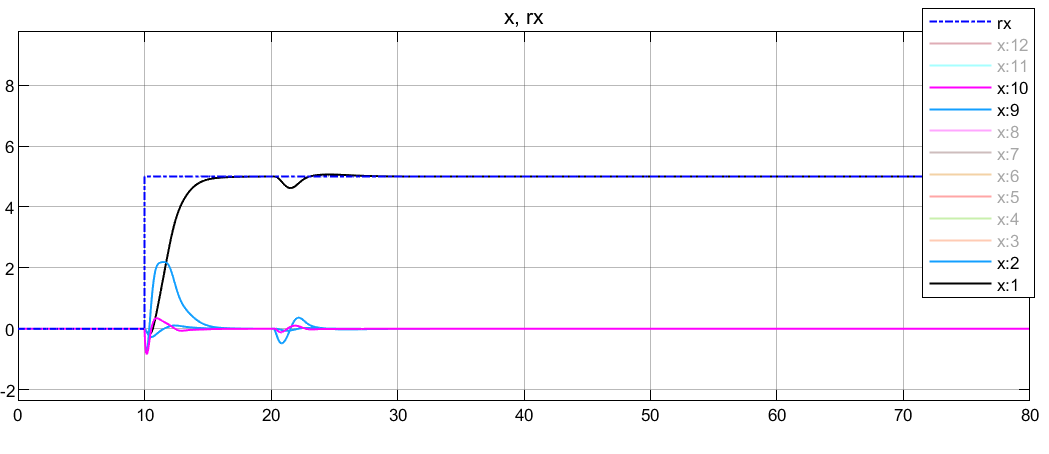

Fig a: Results from the longitudinal(x1, x2, x9, x10) control at constant reference

The dashed line was the reference, and the line tracking the reference was the output of the drone model in the longitudinal direction. From the result, it was observed that the output of the plant tracked the reference input in less than five seconds. The result showed that the controller had good efficiency in controlling the longitudinal motion of the drone. The rise time, the settling time, and the steady-state error showed acceptable results. The drone exhibited stable behavior with good reference tracking at steady state. However, the transient response (overshoot and oscillations) showed some spikes due to extra input in the lateral direction at 20 seconds. It needs some improvement for robustness.

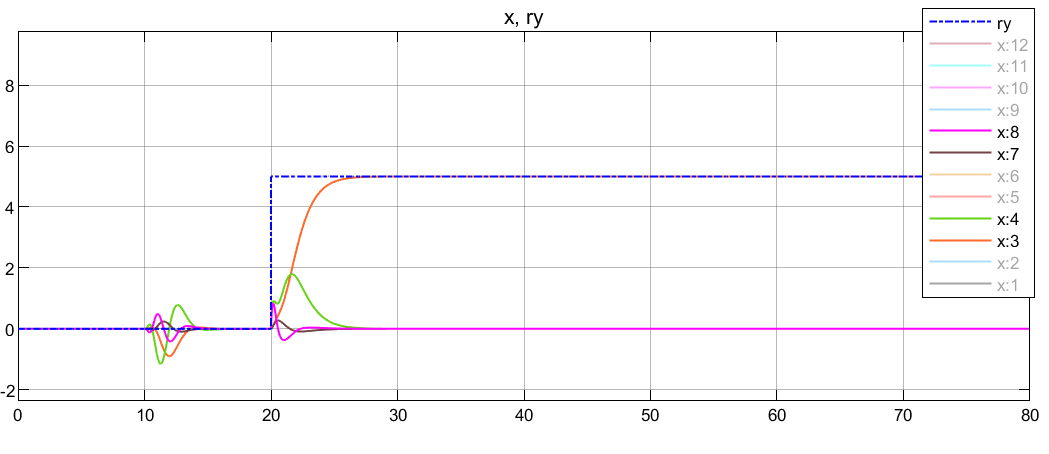

Fig b: Results from the lateral(x3, x4, x7, x8) control at constant reference 

The dashed line is the reference and the line tracking the reference is the output of the drone model in the lateral direction. From the result also, we can see that the output of the plant tracked the reference input in less than five seconds. The result showed that the controller has a good efficiency to control the longitudinal motion of the drone. The rise time, the settling time and the steady state error has shown acceptable results. The drone showed stable behavior with good reference tracking in the longitudinal direction at steady state. However, the transient response (overshoot and oscillations) showed some spikes.

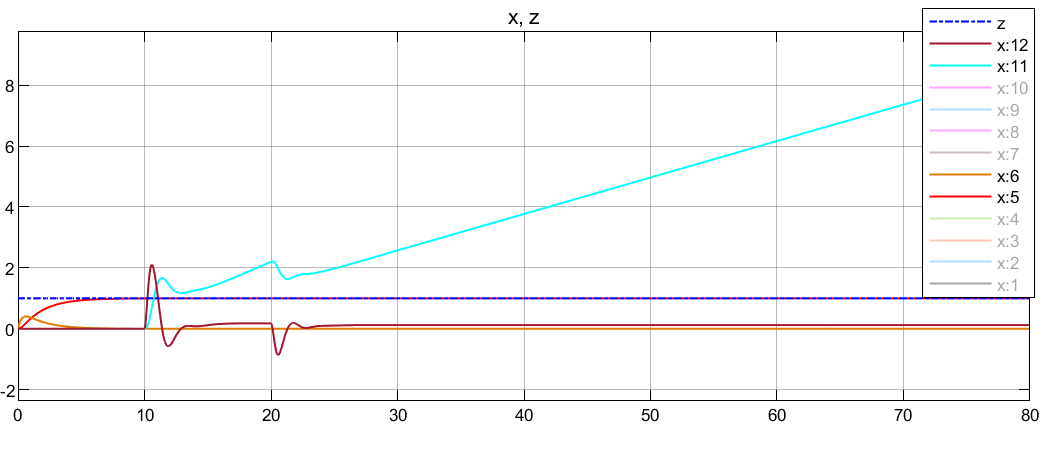

Fig c: Results of the uncontrolled vertical(x5, x6, x11, x12) motion

The vertical motion of the drone is not controlled and the rolling rate shows undesirable(unstable result). So, the vertical motion must be controlled to make the whole system stable. However, the vertical position of the drone is stable.

#### 4. Modify the control input in order to track : 

#### (a) a constant trajectory 

#### 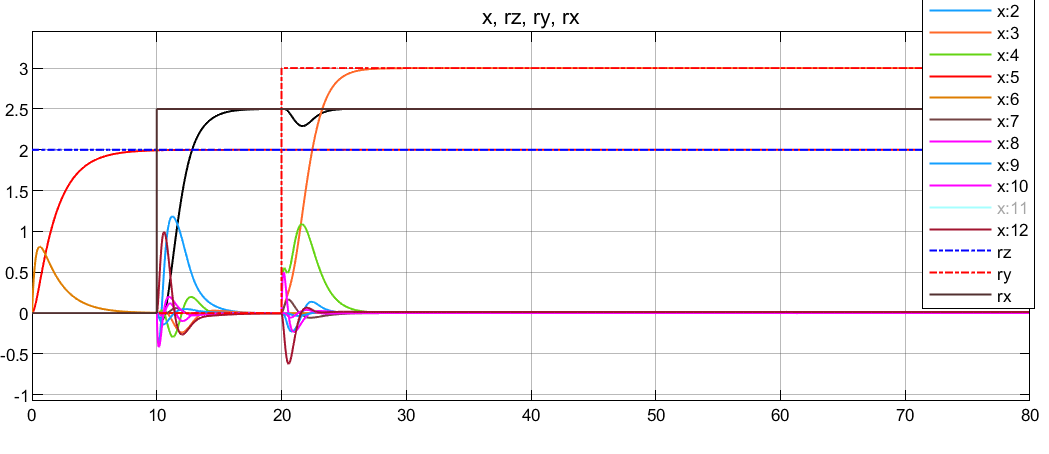

Fig d: The result of the simulation at rx = 2.5, ry = 3 & rz = 2

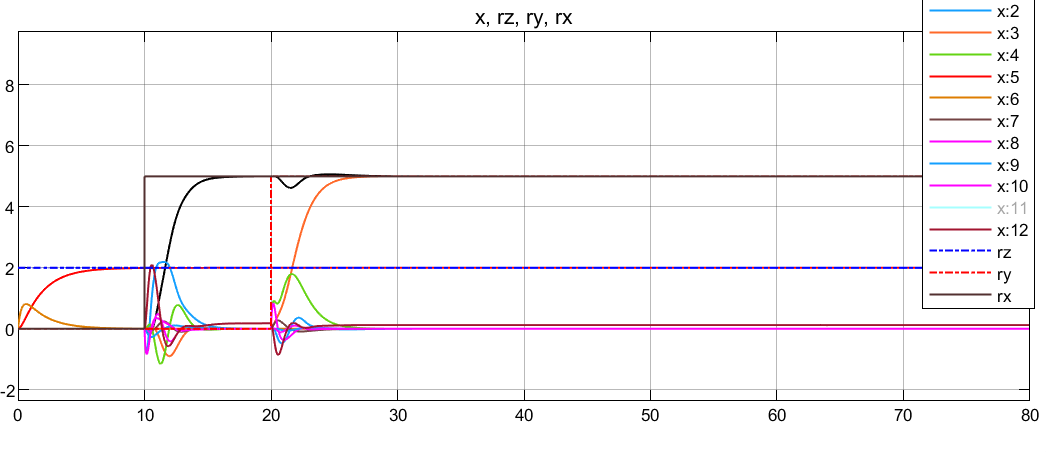

Fig e: The result of the simulation at rx = 5, ry = 5 & rz = 2

From the two results, it could be concluded that the controller had good efficiency at lower reference inputs. When the reference inputs had larger values, there was a higher initial overshoot, but the controller overcame the situation effectively..

#### (b) a time varying trajectory

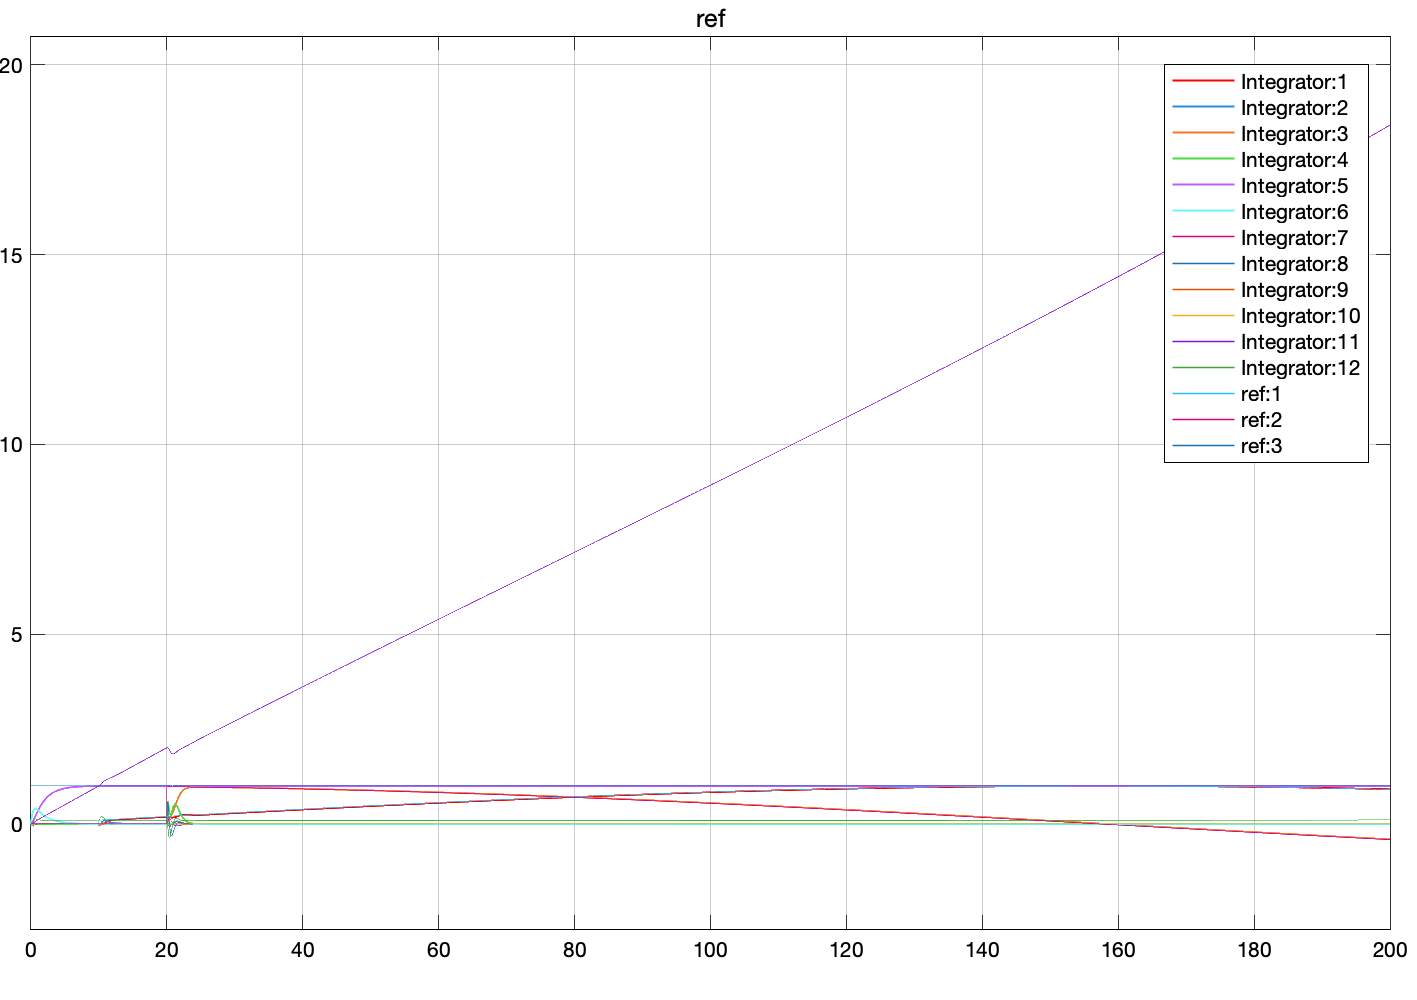

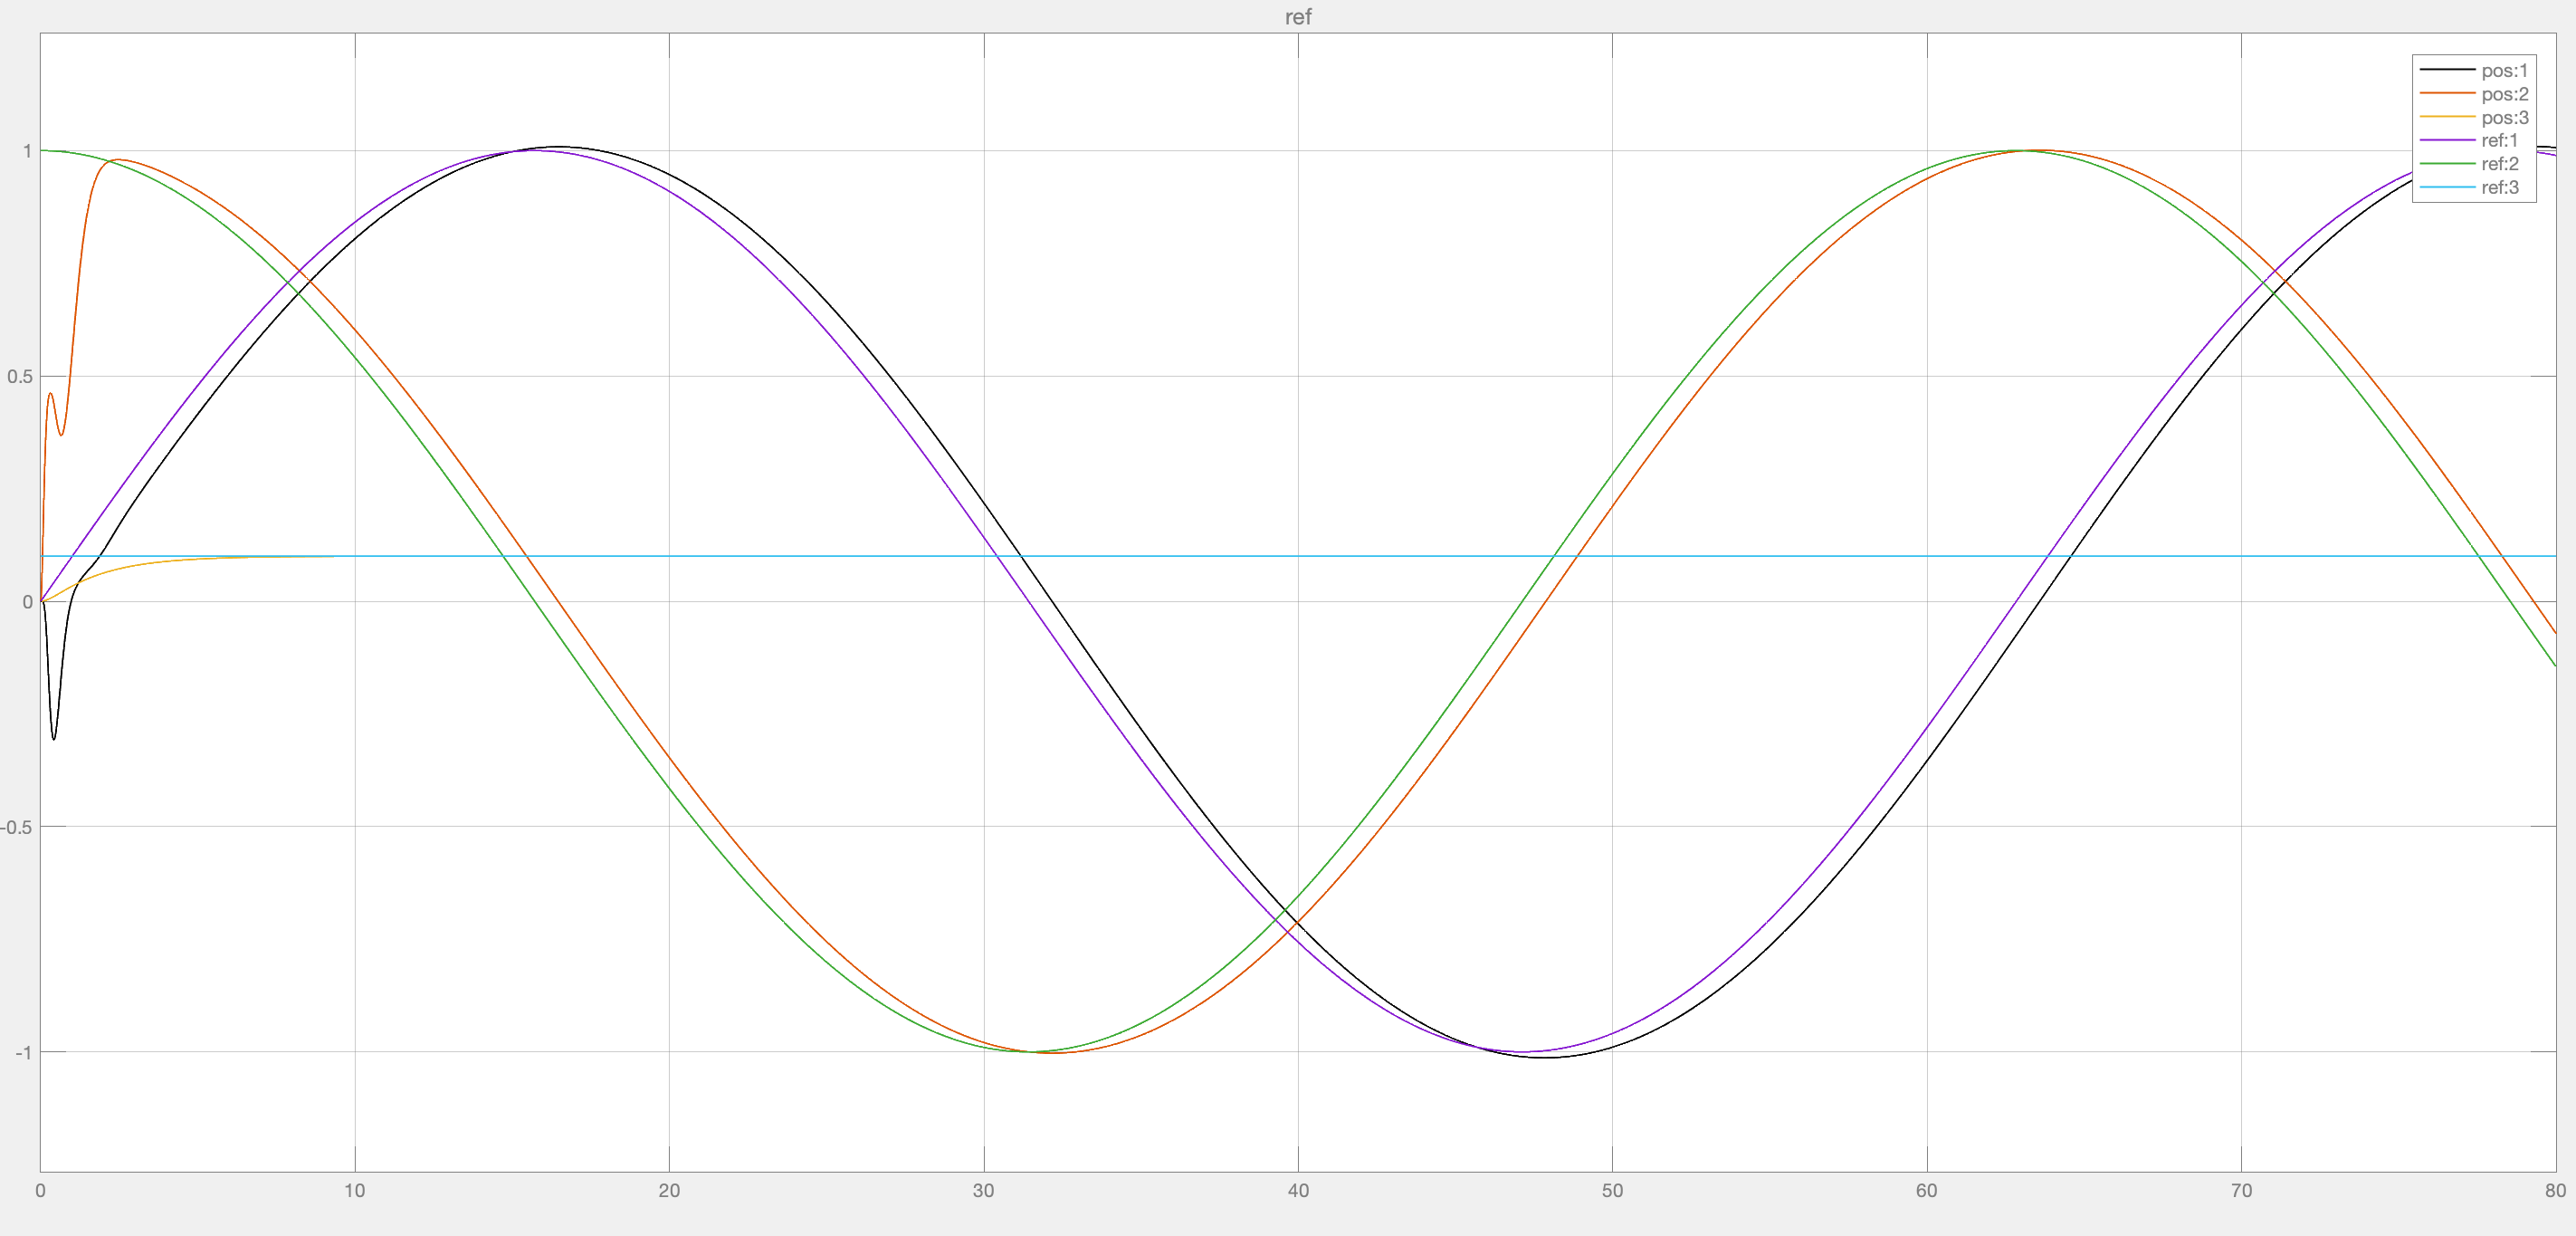

Fig f: The result of the simulation at rx = step(10 sec)*sin(wt), ry = step(20 sec)*sin(wt) & rz = 0.1; w1 = 0.01 rad/s and w2 = 0.1rad/s

The result showed that the controller managed the stability when the reference inputs are time varying. But as we can see from the second figure, the error between reference and output is visibly higher. In real life, this may cause a destruction in the drone. The The efficiency of controllers is measured by their response for sudden changes and the error due to this change. Since this control method has higher errors, we must try another method for the drone control. 

## State feedback with LQR method

Instead of finding K by pole placement, lets use the LQR method with cost function. 

**Quadratic Cost Function**: The goal of an LQR controller is to minimize a cost function of the form:


$$J = \int_0^\infty \left( x(t)^T Q x(t) + u(t)^T R u(t) \right) dt
$$


- Q is a positive semi-definite matrix that penalizes deviations in the state x(t).

- R is a positive definite matrix that penalizes the control effort u(t).

- The integral computes the cost over time, and the objective is to minimize this cost by choosing the optimal control input u(t).

From Ricatti equation of the form:


$$P A + A^T P - P B R^{-1} B^T P + Q = 0
$$
        

We can use the function [K, P] = lqr(A, B, Q, R) to find the value of **K**; where **P is the solution of the Ricatti equation**

Here, we can play on the Q & R values that penalize the the state deviation or the control effort. Lets define a simple Q & R values, R = I and Q = 0.01*I, where I - is identity matrix

clc;
% longitudinal control
Q = 360*eye(4);
R = 30*eye(1);
A = [0 1 0 0; 0 0 -9.81 0; 0 0 0 1; 0 0 0 0];
B =[0; 1; 0; 1];
C = eye(4);
[K1,S,P] = lqr(A, B, Q, R)
A1 = inv(A - (B*K1));

K2 =     3.4641    5.1527   20.6030    3.3405


S = 1.0e+03 *

    0.5355    0.2183    0.3472   -0.1143
    0.2183    0.2893    0.6307   -0.1347
    0.3472    0.6307    3.3860   -0.0126
   -0.1143   -0.1347   -0.0126    0.2349


P =   -0.9366 + 2.2733i
  -0.9366 - 2.2733i
  -1.0004 + 0.0000i
  -5.6197 + 0.0000i


V_mat1 = -pinv(C*A1*B);

% lateral control
A2 = [0 1 0 0; 0 0 9.81 0; 0 0 0 1; 0 0 0 0];
B2 =[0; 1; 0; 1];
C2 = eye(4);
D = 0;
[K2,S,P] = lqr(A2, B2, Q, R)
A21 = inv(A2 - (B2*K2));
V_mat2 = -pinv(C2*A21*B2);


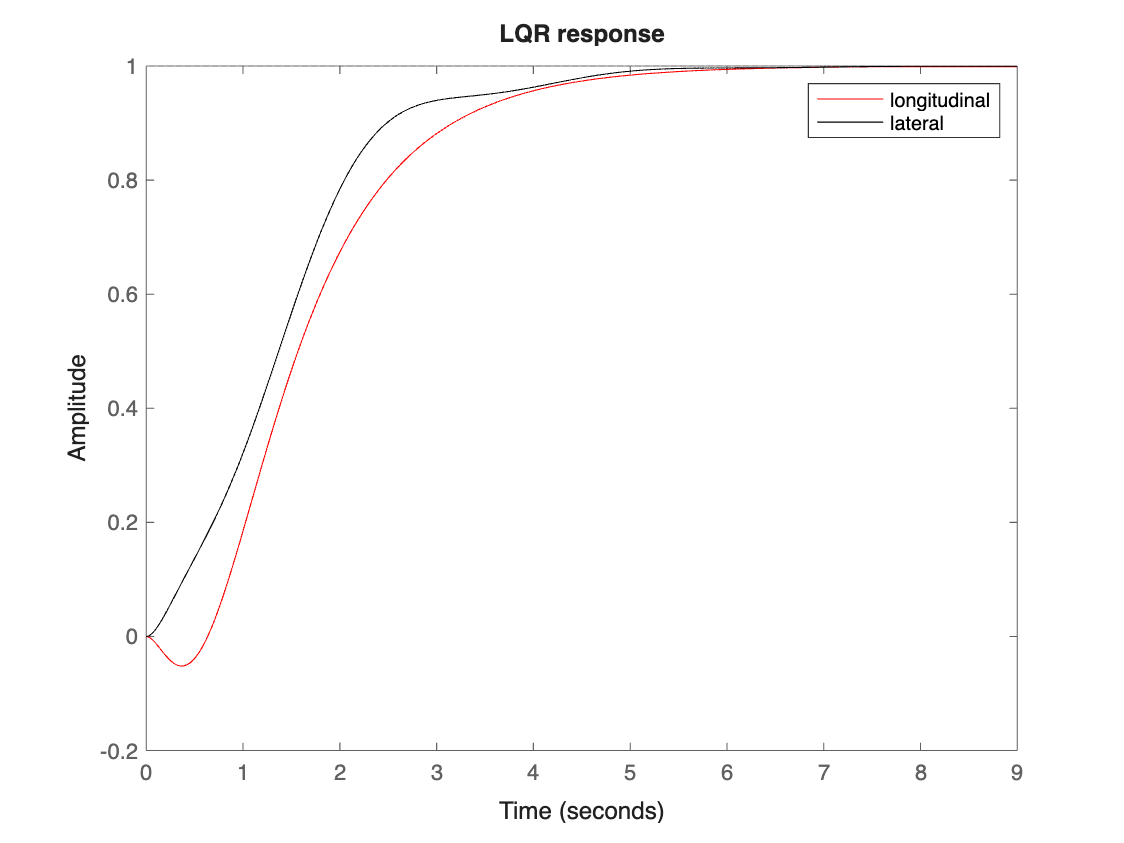

%%%
% State-Space for Longitudinal with pole placement
lon_pole = ss(A - B*K1, B, C, D); 

% Step Responses for Longitudinal Models figure;
step(lon_pole(1)/dcgain(lon_pole(1)), 'r-'); 

hold on;

% State-Space for Longitudinal with pole placement
lat_pole = ss(A2 - B2*K2, B2, C2, D); 


% Step Responses for Longitudinal Models figure;
step(lat_pole(1)/dcgain(lat_pole(1)), 'k-'); 
hold off;

legend('longitudinal', 'lateral');
title('LQR response');

As we can see the result, the step response of the LQR method is settled in 5 seconds. Compared to the pole placement, **it took more time to settle**, so the controller **seems less efficient** than the pole placement method in the linear state space model. This discrepancy may be attributed due to the optimization process inherent in LQR, which prioritize certain criteria over achieving an exact match with the chosen pole locations. Lets apply it to the nonlinear plant compare results. 

Now, lets try the new K value on the nonlinear model and see the result.

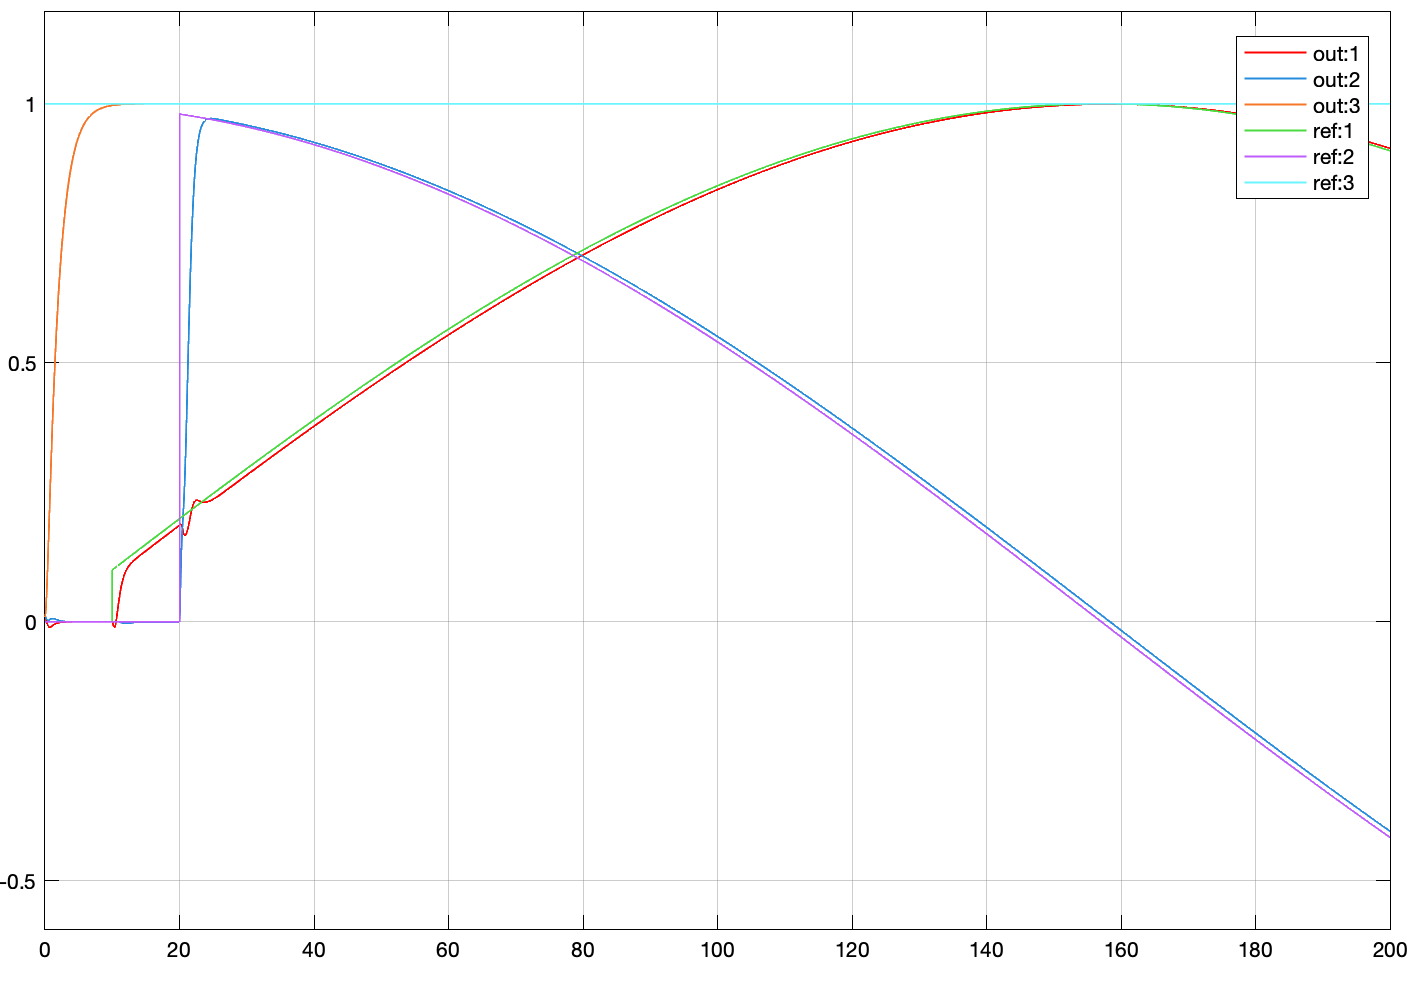

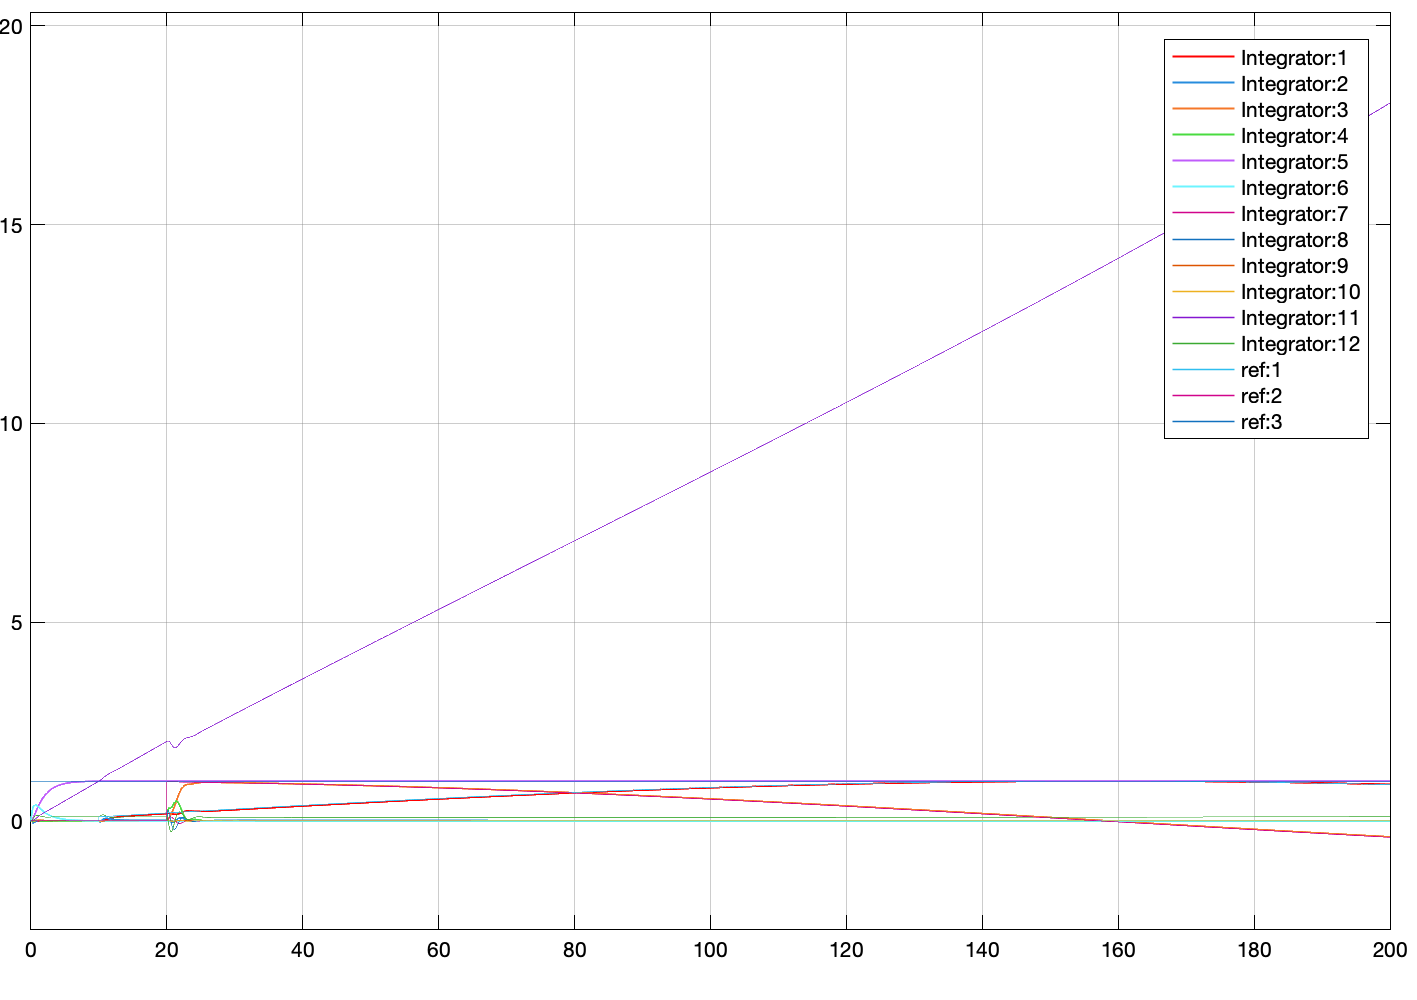

Fig g: The result of the simulation at rx = step(10sec)*sin(wt), ry = step(20sec)*sin(wt) & rz = 0.1; w = 0.01rad/s

As we see from the first figure, the output tracked the reference with better efficiency than pole placement. However the yaw component of the drone is unstable like the previous control method. 

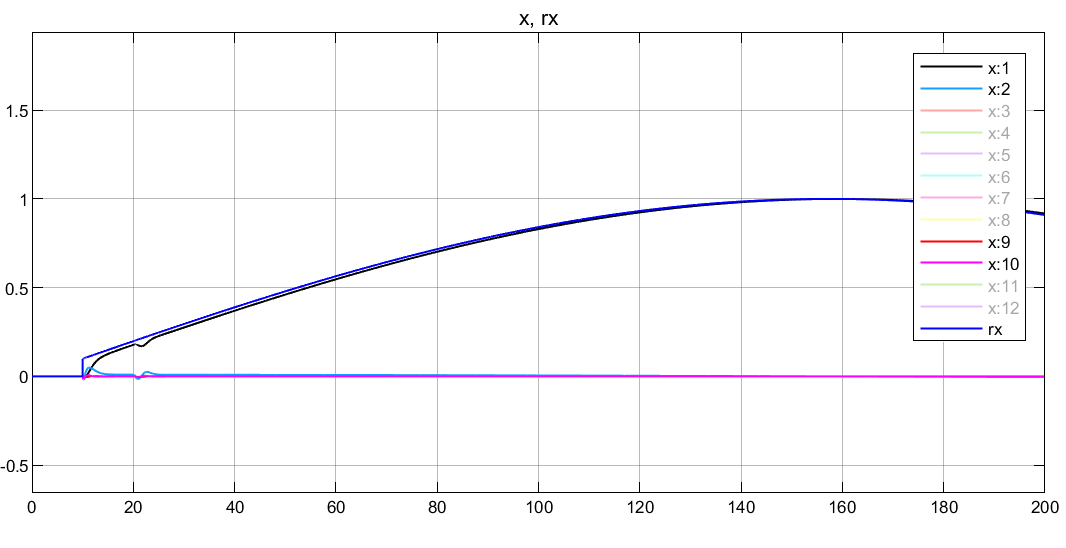

Figure h: Fig a: Results from the longitudinal(x1, x2, x9, x10) control at variable reference

As shown in figure h, the system demonstrates good reference tracking for the longitudinal motion under variable reference. While there is some overshoot and slight oscillations during the transient phase, the controller successfully stabilizes the system and achieves effective tracking of the reference signal.

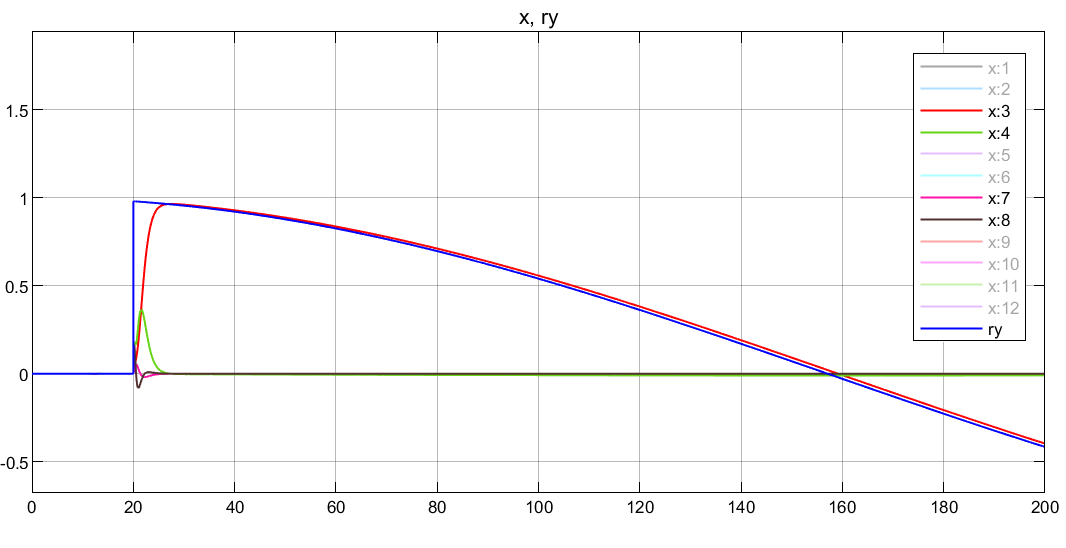

Figure i: Fig a: Results from the lateral l(x3, x4, x7, x8) control at variable reference

As shown in figure i, the system demonstrates good reference tracking for the lateral motion under variable reference. While there is some overshoot and slight oscillations during the transient phase, the controller successfully stabilizes the system and achieves effective tracking of the reference signal.

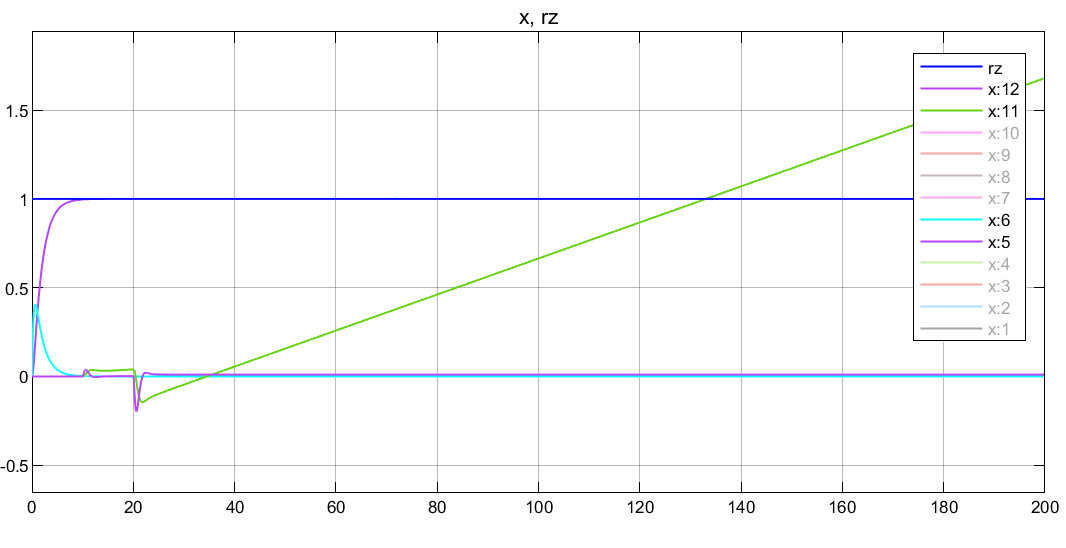

Figure j: Fig a: Results of the uncontrolled vertical(x5, x6, x11, x12) motion

As shown in figure , the z-position successfully tracks the reference signal rz, achieving steady-state stability after an initial transient phase. However, the yaw angle (x:11) becomes unstable, showing a continuous increasing . This behavior suggests a lack of control robustness in the yaw direction.

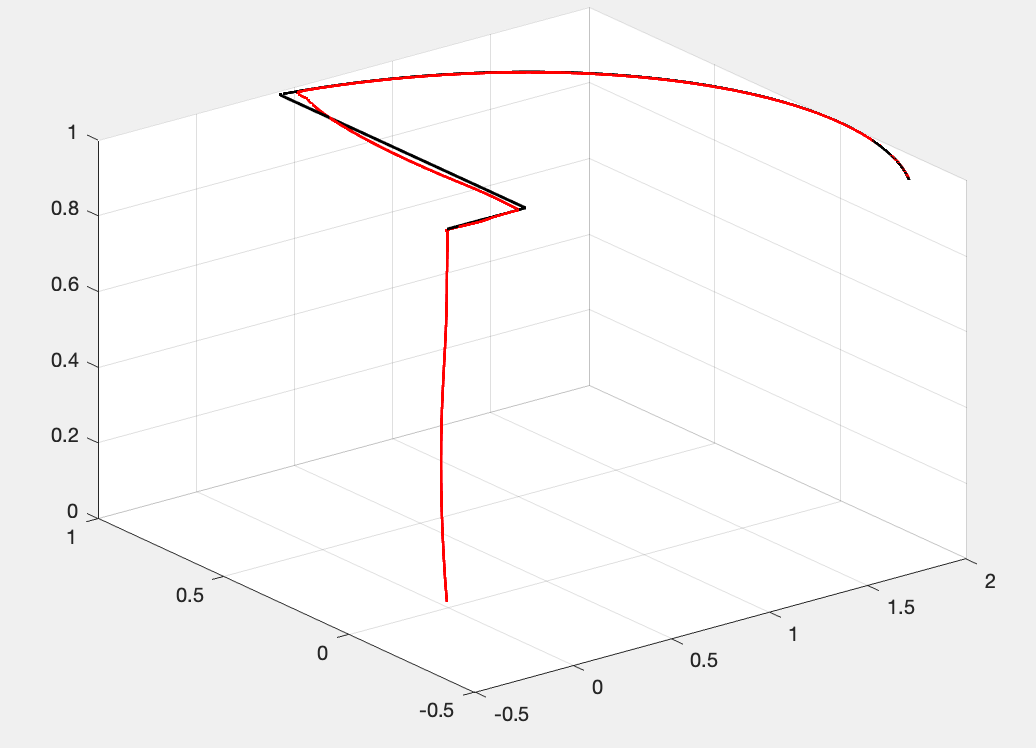

Fig h: 3D plot of the robot position at w = 0.01rad/s and simulation time 200s (black - reference, red - output)

The 3D plot of the position output of the drone is not a full circle at the top due to low frequency and or short simulation time. And, it didn't track the linear component exactly, while it tracked the angular motion efficiently. 

# 2. Nonlinear longitudinal and lateral control

#### **1. For each motion, compute a nonlinear controller by state feedback control with exact linearization approach.**

i. Define the system dynamics 

                        longitudinal motion                           lateral motion


$$
\dot{x_1} = x_2 \\
\dot{x_2} = x_{12}x_4 - x_{10}x_6 - g \sin x_9 + u_1 \\
\dot{x_9} = x_{10} \\
\dot{x_{10}} = a_2x_{12}x_8 + b_2u_1 \\$$
            
$$
\dot{x_3} = x_4 \\
\dot{x_4} = x_8x_6 - x_{12}x_2 + g \sin x_7 \cos x_9 + u_2 \\
\dot{x_7} = x_8 \\
\dot{x_8} = a_1 x_{12}x_{10} + b_1u_2 \\$$


ii. Choose an output to control

Assume that the desired output is one of the states. Let's choose **y = x_1** for longitudinal and **y_2 = x_3** for lateral motions, which represents the longitudinal and lateral positions of the drone respectively.

To apply exact linearization, we need to compute the relative degree of the system with respect to **y=x_1 and y_2 = x_3**. 

Compute derivatives of **y until u_1** appears and **y_2 until u_2** appears

$ 
\dot{y}  = \dot{x_1} = x_2 \\
\ddot{y}  = \dot{x_2} = x_{12}x_4-x_{10}x_6-gsin (x_9)+u_1
$      ;      $ 
\dot{y}_2  = \dot{x_3} = x_4 \\
\ddot{y}_2  = \dot{x_4} = x_8 x_6 - x_{12}x_2+gsin (x_7)cos(x_9) + u_2
$

Here, u_1 and u_2 appears in the second derivative of y and y_2. Hence, the relative degree of the system with respect to **y = x_1 and y_2 = x_3** is 2. 

iii. Linearize the system (Feedback Linearization)

The general form for the second-order system is: **ddy = v, and ddy_2 = v_2** where **v and v_2** are new (fictitious) control inputs.

**Now lets define the control law for** **u_1 and u_2**

We can rewrite the equations as:

$ 
\ddot{y}  = v, \ then \\
u_1 = v - (x_{12}x_4-x_{10}x_6-gsin (x_9))
$     ;    $ 
\ddot{y}_2  = v_2, \ then \\
u_2 = v_2 - (x_8 x_6-x_{12}x_2+gsin (x_7)cos(x_9))
$

This control law effectively cancels the nonlinearities in the system, transforming the system into **ddy = v and ddy_2 = v_2**.

iv. Control design for v and v_2

We now design **v and v_2 to make y and y_2 **track a desired trajectory **y_desired and y_2_desired**. Using a second-order error dynamics model:


$$\ddot{e} + 2 \zeta \omega_n \dot{e} + \omega_n^2 e = 0
$$


The control law for **v_long and v_lat **can be chosen as:


$$v = \ddot{y}_{\text{desired}} + k_p (y_{\text{desired}} - y) + k_d (\dot{y}_{\text{desired}} - \dot{y})
$$



$$v_2 = \ddot{y_2}_{\text{desired}} + k_{p2} (\dot{y_2}_{\text{desired}} - y_2) + k_{d2} (\dot{y_2}_{\text{desired}} - \dot{y_2})$$


where the control gains are:

$k_p = \omega_n^2, \quad k_d = 2 \zeta \omega_n
$       and      $k_{p2} = \omega_{n2}^2, \quad k_{d2} = 2 \zeta \omega_{n2}
$

Here to design the gains numerically, we can use $\zeta$**= 1** for perfect tracking and $\omega $ based on our requirement lets say $\omega _ n = 2$** and **$\omega _{n2} = 4$

then, 

k_p = 4; k_p2 = 16; k_d = 4; k_d2 = 8;

The other method to design the gain values is using matrix method and go back to Ackerman's method in the matlab by selecting a desired poles. 

z - is the transformed state 


$$z = [z_1; z_2] \\
\dot{z_1} = x_2 \ and\ \dot{z_2} = v = f(x) + g(x)u \\
\dot{z} = Az + Bv \ where \ v = -Kz \\
\dot{z} = (A-BK)z$$


A = [0 1; 0 0]; % in the transformed state longitudinal and 
% lateral motions have the same A and B matrix
B = [0; 1];
C = [1 0];
D =  0;
p1 = [-6; -9] % desired poles in the transferred domain

p1 =     -6
    -9


K1 = acker(A, B, p1) % for longitudinal K1 = [kp1 kd1]

K1 =     54    15


p2 = [-4; -5]

p2 =     -4
    -5


K2 = acker(A, B, p2) % for lateral K2 = [kp2 kd2]

K2 =     20     9


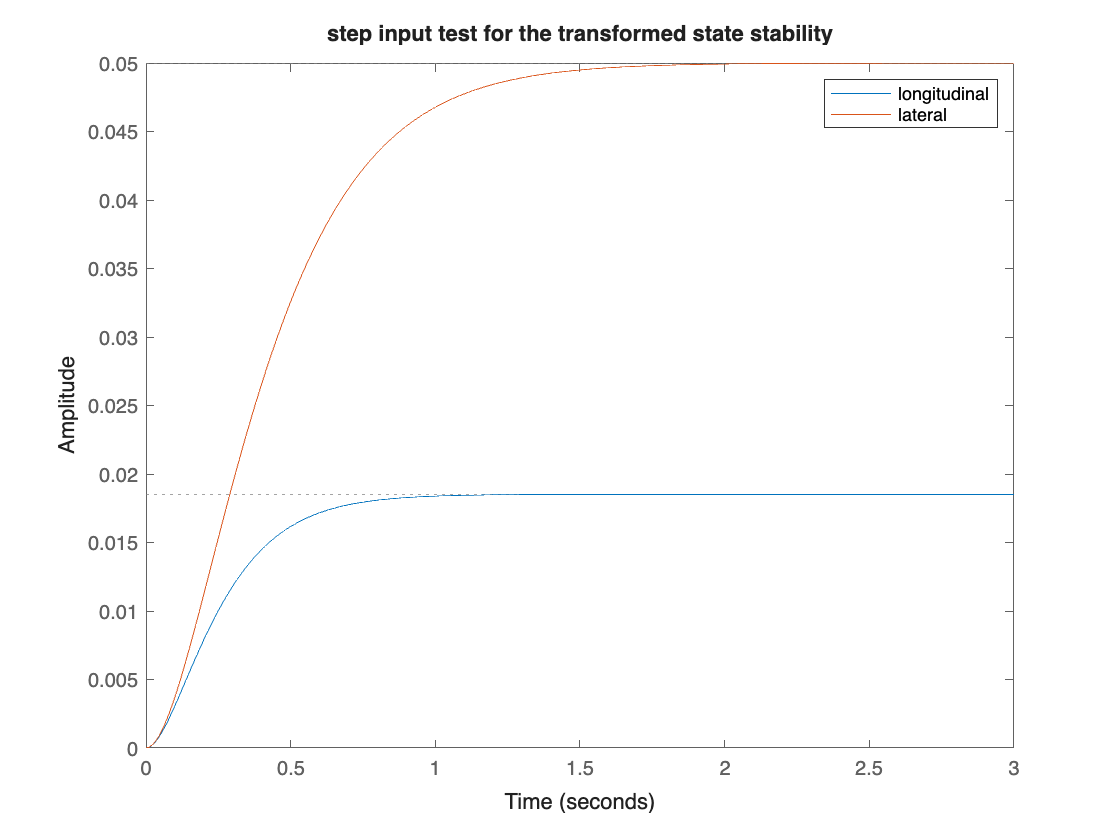

z_ss1 = ss(A-B*K1, B, C, D);
step(z_ss1);
hold on
z_ss2 = ss(A-B*K2, B, C, D);
step(z_ss2)
hold off
legend('longitudinal', 'lateral')
title('step input test for the transformed state stability')

As we see from the step response, the transformed state model is stable, so we can apply this into the nonlinear plant.

v. Finally,

The control input **u_1 and u_2** can be expressed as below:


$$u_1 = \ddot{y}_{\text{desired}} + k_p (y_{\text{desired}} - y) + k_d (\dot{y}_{\text{desired}} - \dot{y}) - (x_{12} x_4 - x_{10} x_6 - g \sin(x_9))
$$



$$e = y_{\text{desired}} - y \\
\dot{e} = \dot{y}_{\text{desired}} - \dot{y} \\
u_1 = \ddot{y}_{\text{desired}} + k_p e + k_d \dot{e} - (x_{12} x_4 - x_{10} x_6 - g \sin(x_9))
$$



$$u_2 = \ddot{y_2}_{\text{desired}} + k_{p2} ({y_2}_{\text{desired}} - y_2) + k_{d2} (\dot{y_2}_{\text{desired}} - \dot{y_2}) - (x_{8} x_6 - x_{12} x_2 + g \sin(x_7)cos(x_9))
$$



$$e_2 = {y_2}_{\text{desired}} - y_2 \\
\dot{e_2} = \dot{y_2}_{\text{desired}} - \dot{y_2} \\
u_2 = \ddot{y_2}_{\text{desired}} + k_{p2} e_2 + k_{d2} \dot{e_2} - (x_8 x_6 - x_{12} x_2 +g \sin(x_7)cos(x_9))
$$


#### **2. Apply the proposed control techniques directly on the nonlinear model. Discuss the results. **

The reference input for our system in the longitudinal direction is **rx**. So, we can replace the desired input by **rx** and try the controller on the nonlinear model. In the lateral direction, the reference input is **ry**. To include the first and second derivative of the reference input into the system, we can use a differential blocks in the simulink block and include the derivatives in the matlab function as input parameter. In the constant input, the derivatives of the reference inputs are zero and we can skip. But for the time varying it can't be zero. So, to make it a generalized model, we should include the differentials in the equations. **Here, I am using a pure feedback with exact linearization, so it is also possible to remove the feedforward input (the second derivative of the reference). Below is the modified simulink model: **

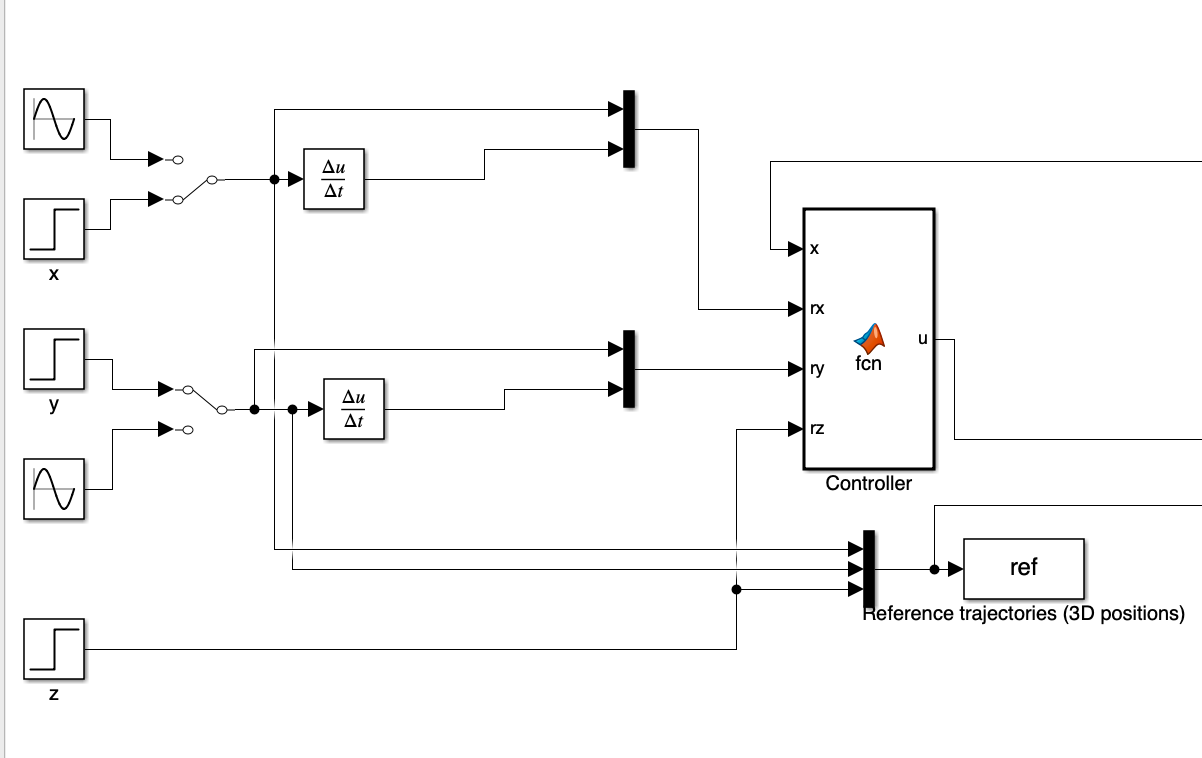

Fig i.a: modified simulink block with reference derivatives

The manual switch block is used to change references


% longitudinal control
u(1) = K1(1)*(rx(1)-x(1))+K1(2)*(rx(2)-x(2))-(x(12)*x(4)-x(10)*x(6)-g*sin(x(9)));

% lateral control

u(2) = K2(1)*(ry(1)-x(3))+K2(2)*(ry(2)-x(4))-(x(8)*x(6)-x(12)*x(2)+g*sin(x(7))*cos(x(9)));

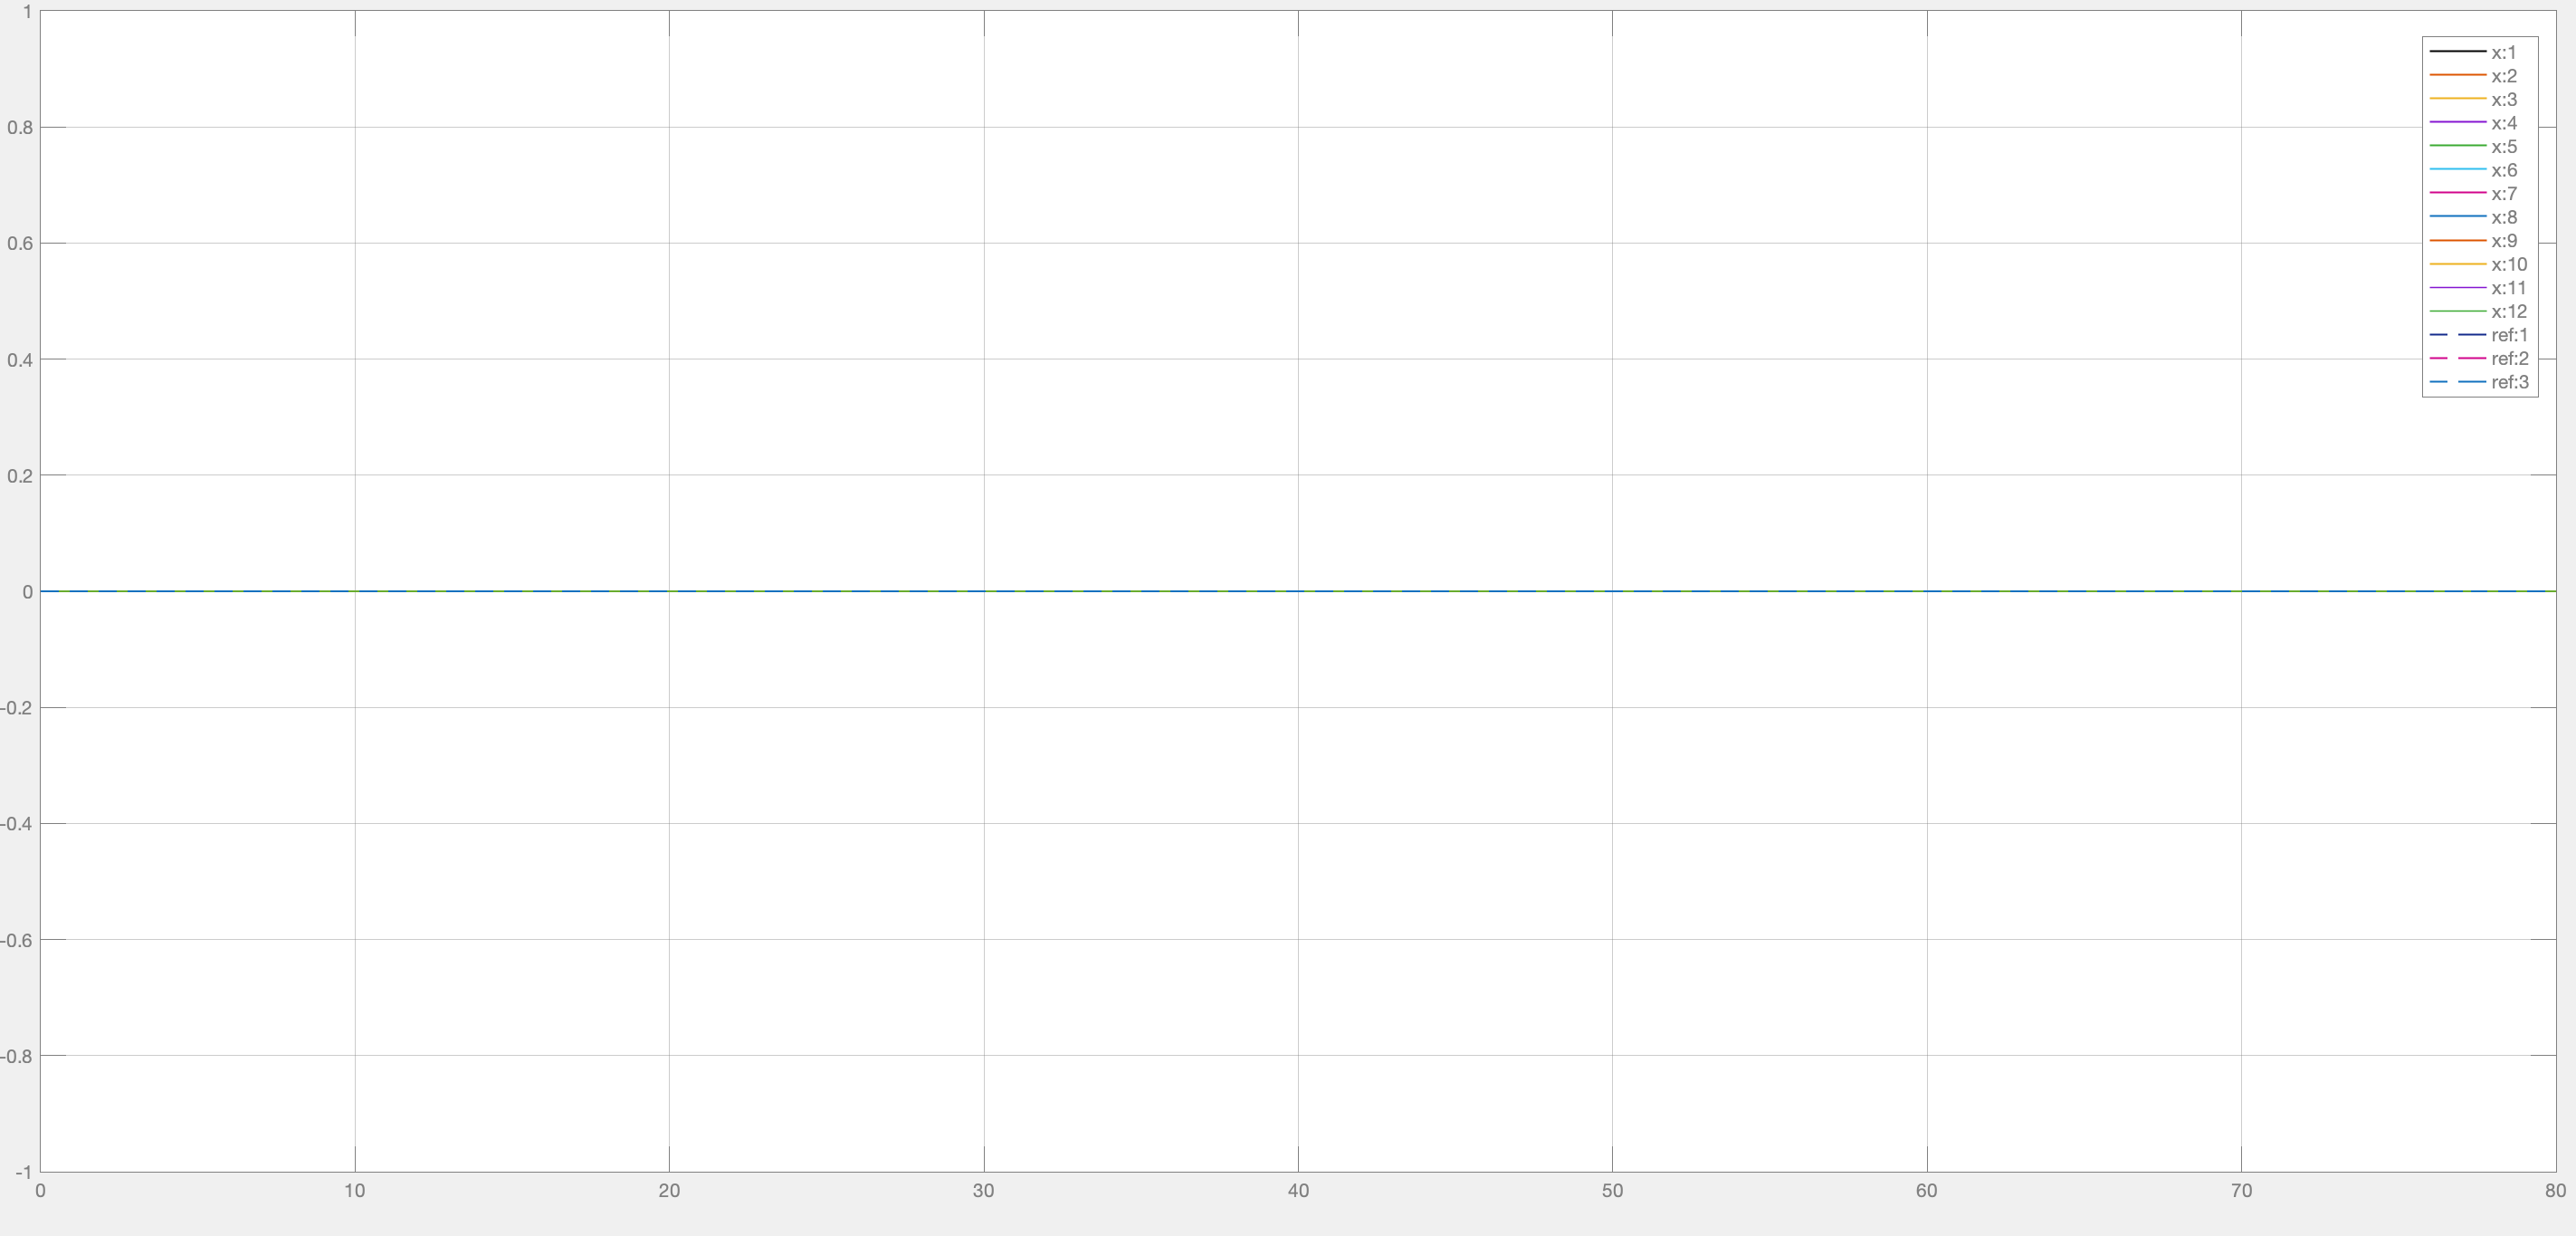

Fig i.b : zero reference response of the drone model

As we can see from the result, the whole states are stable at the origin. This justified that our system is linearized perfectly at the origin and near to the origin.

#### **3. Modify the control input in order to track: **

(a) a constant trajectory 

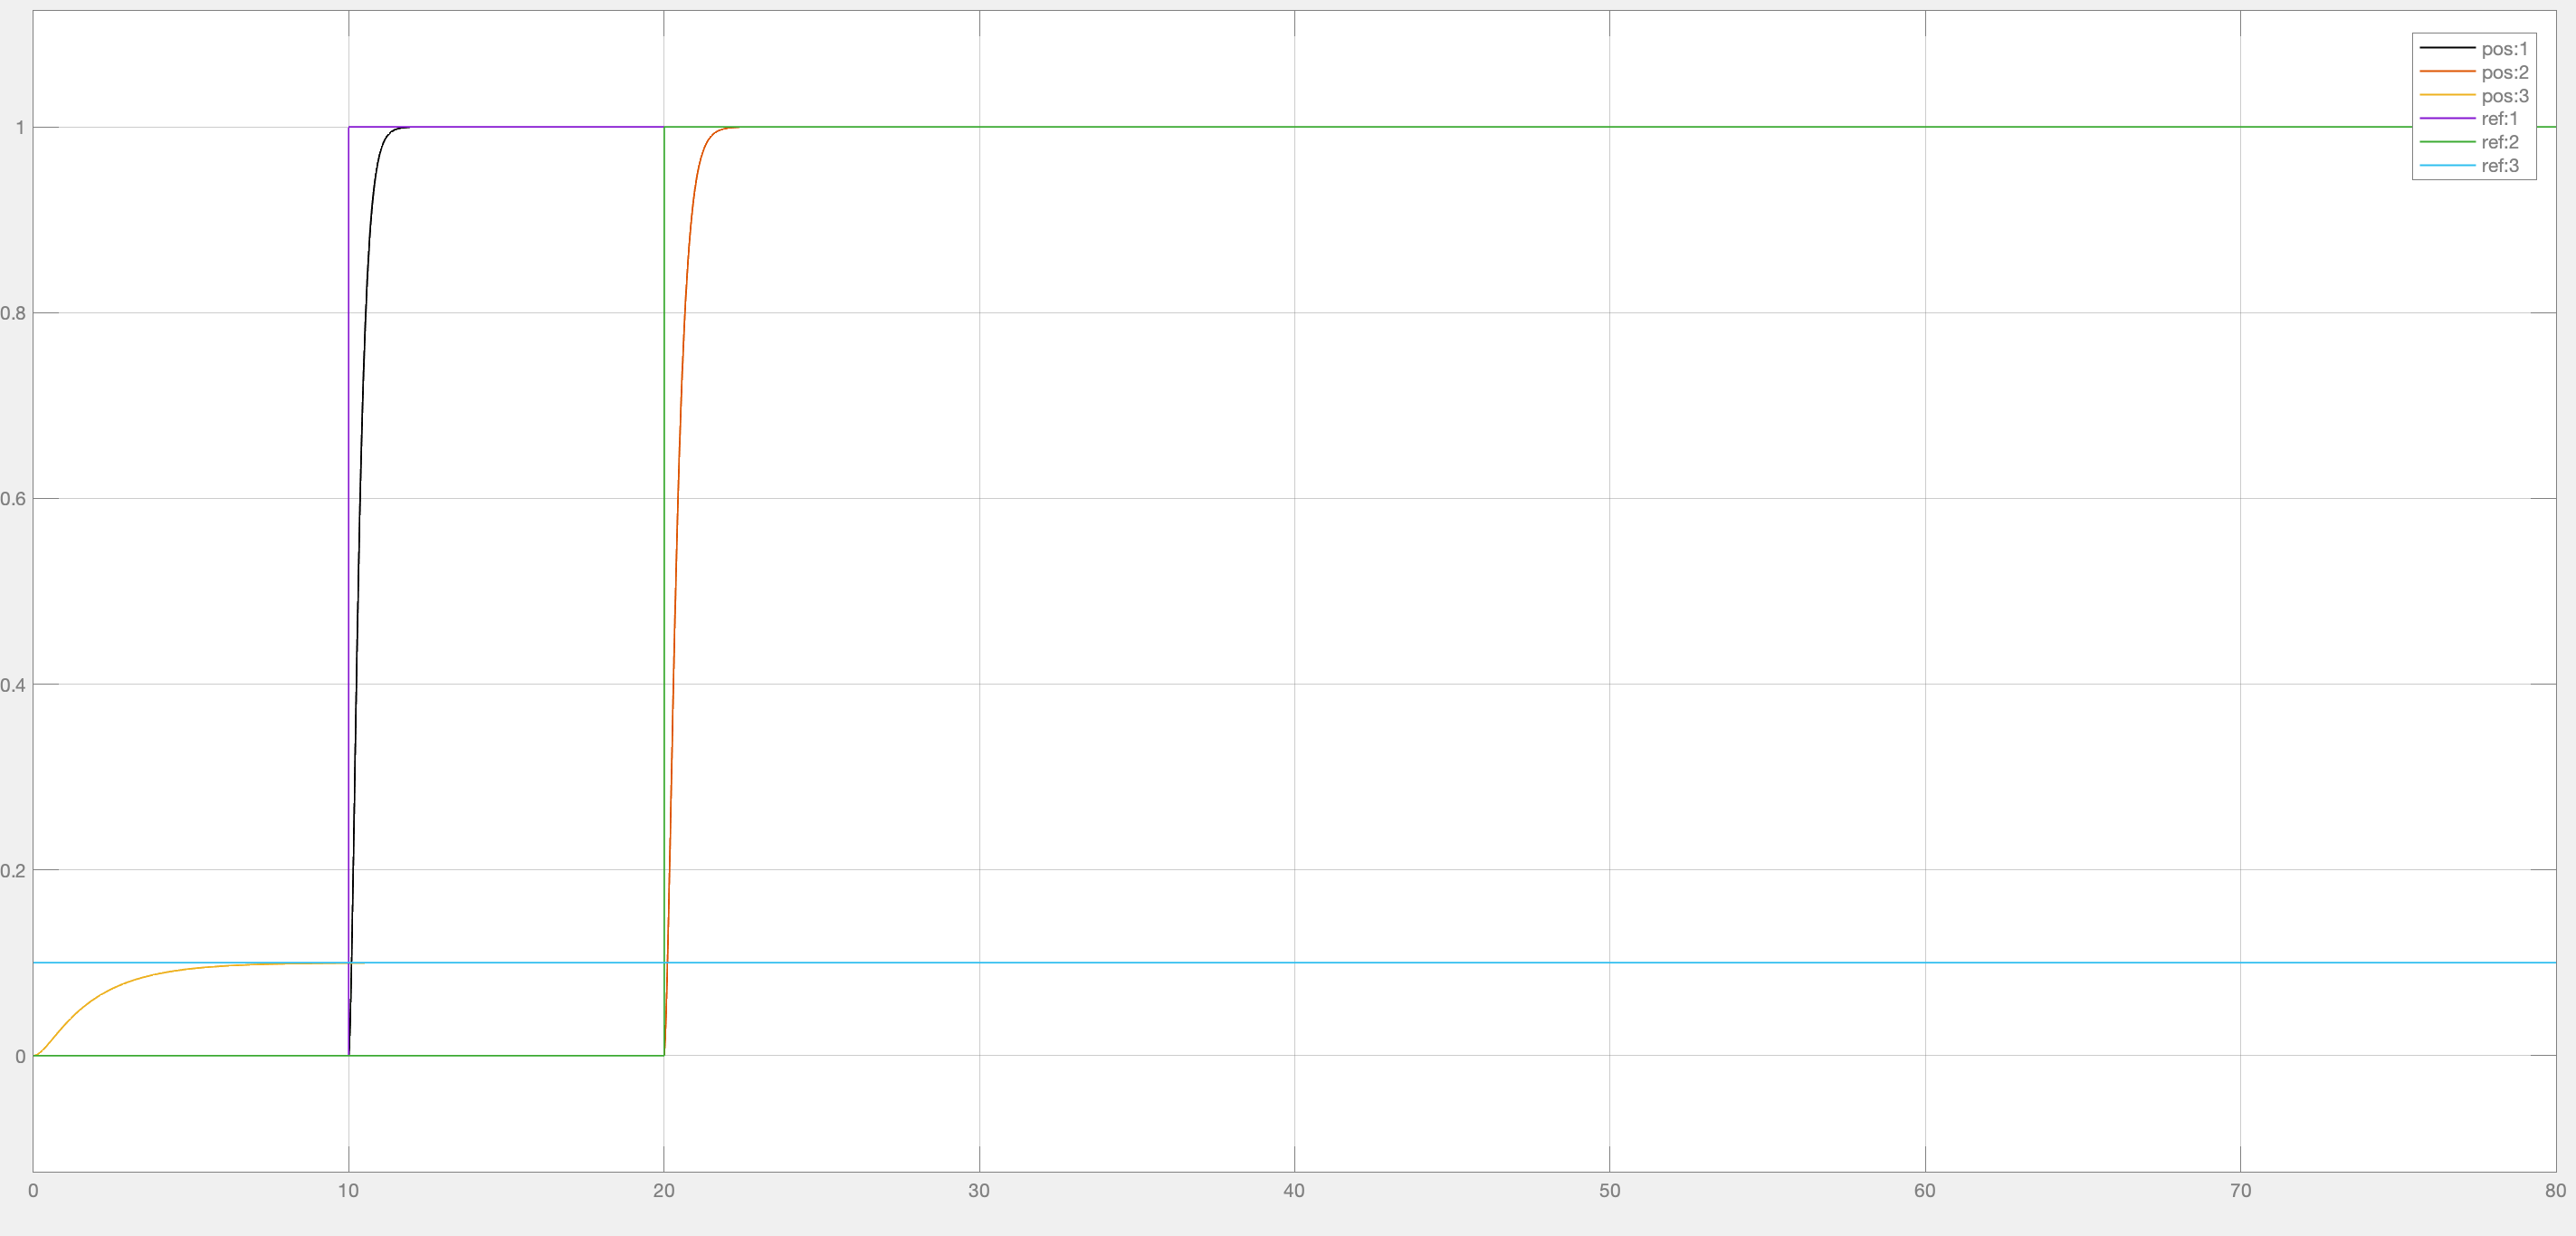

Fig j.a: constant input responses (linear positions (x1,x3, x5))

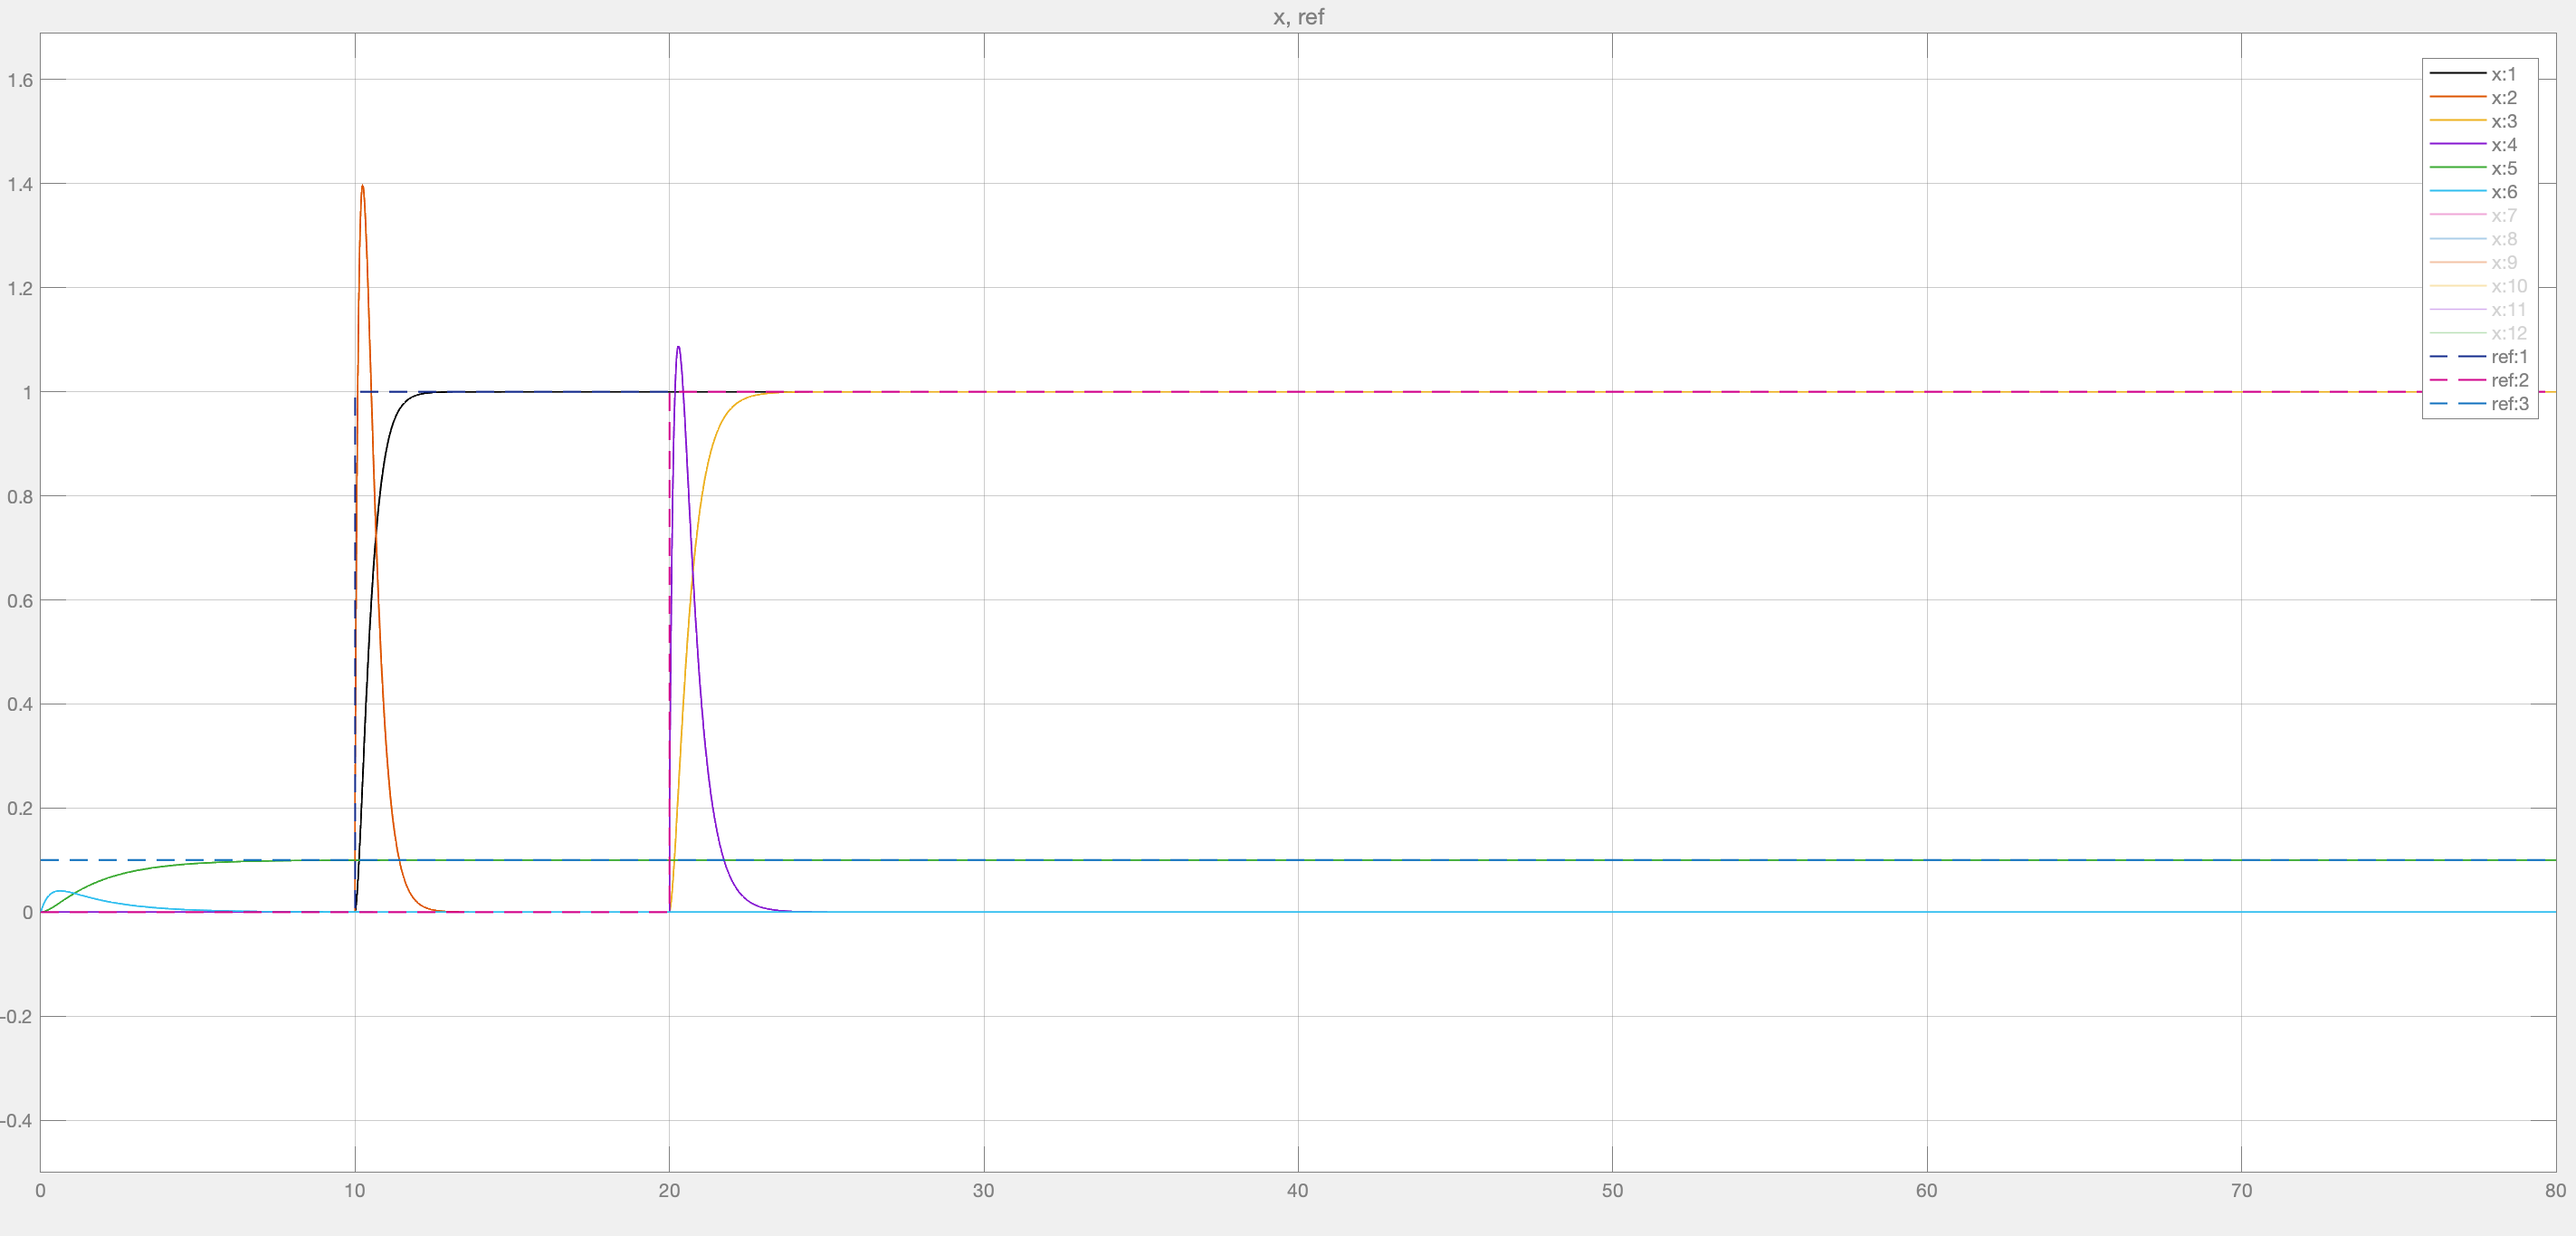

Fig j.b: constant input responses (linear positions and velocities (x1-x6))

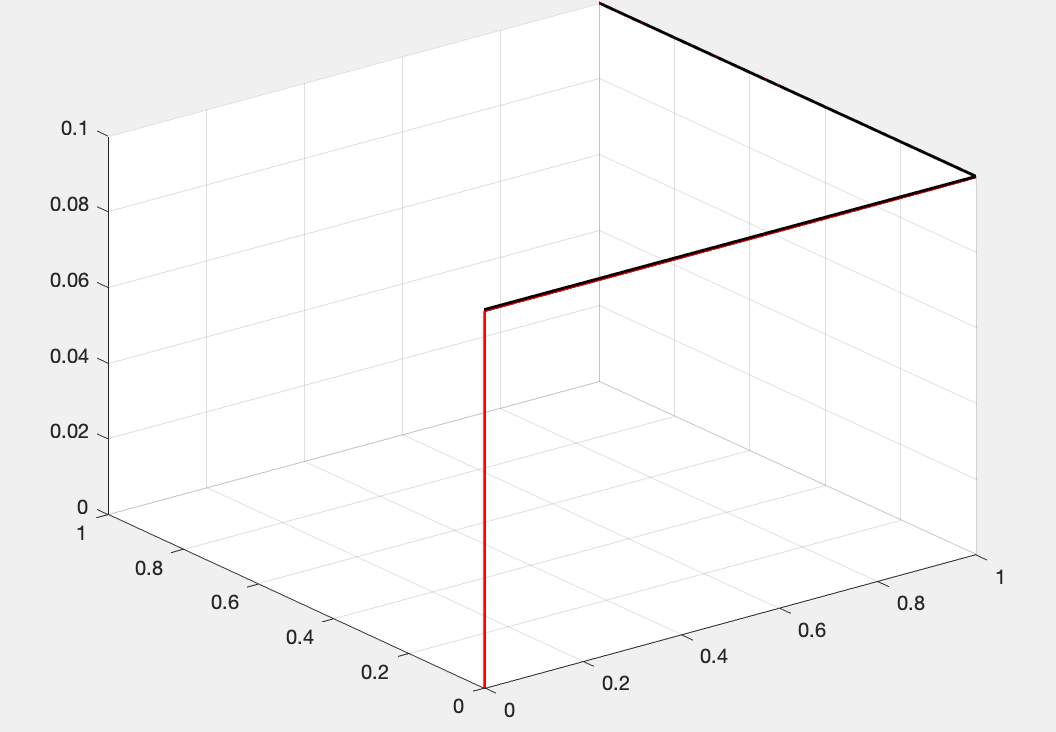

Fig j.c: plot in 3D for the constant inputs (black - reference, red - output)

In the constant input, our exact linearized plant perfectly tracked the reference input. The settling time is around 1 second after excitation and the error is zero afterward. Unlike the the previous methods, now the angular positions and velocities are unstable while the linear positions and velocities are perfectly controlled. **This is due to the relative degree of the output is 2, while the dimensions of the states are 4.** In the linearization process we only considered the controllable states (the linear position and velocity). **To control the angular positions and velocities, we must choose an output with a relative degree of 4 OR take the states as internal dynamics and stabilize them at lower relative degrees.** Since they are angular values, we can also set a saturation limit in range of [-pi, pi] for the angular positions.

(b) a time varying trajectory

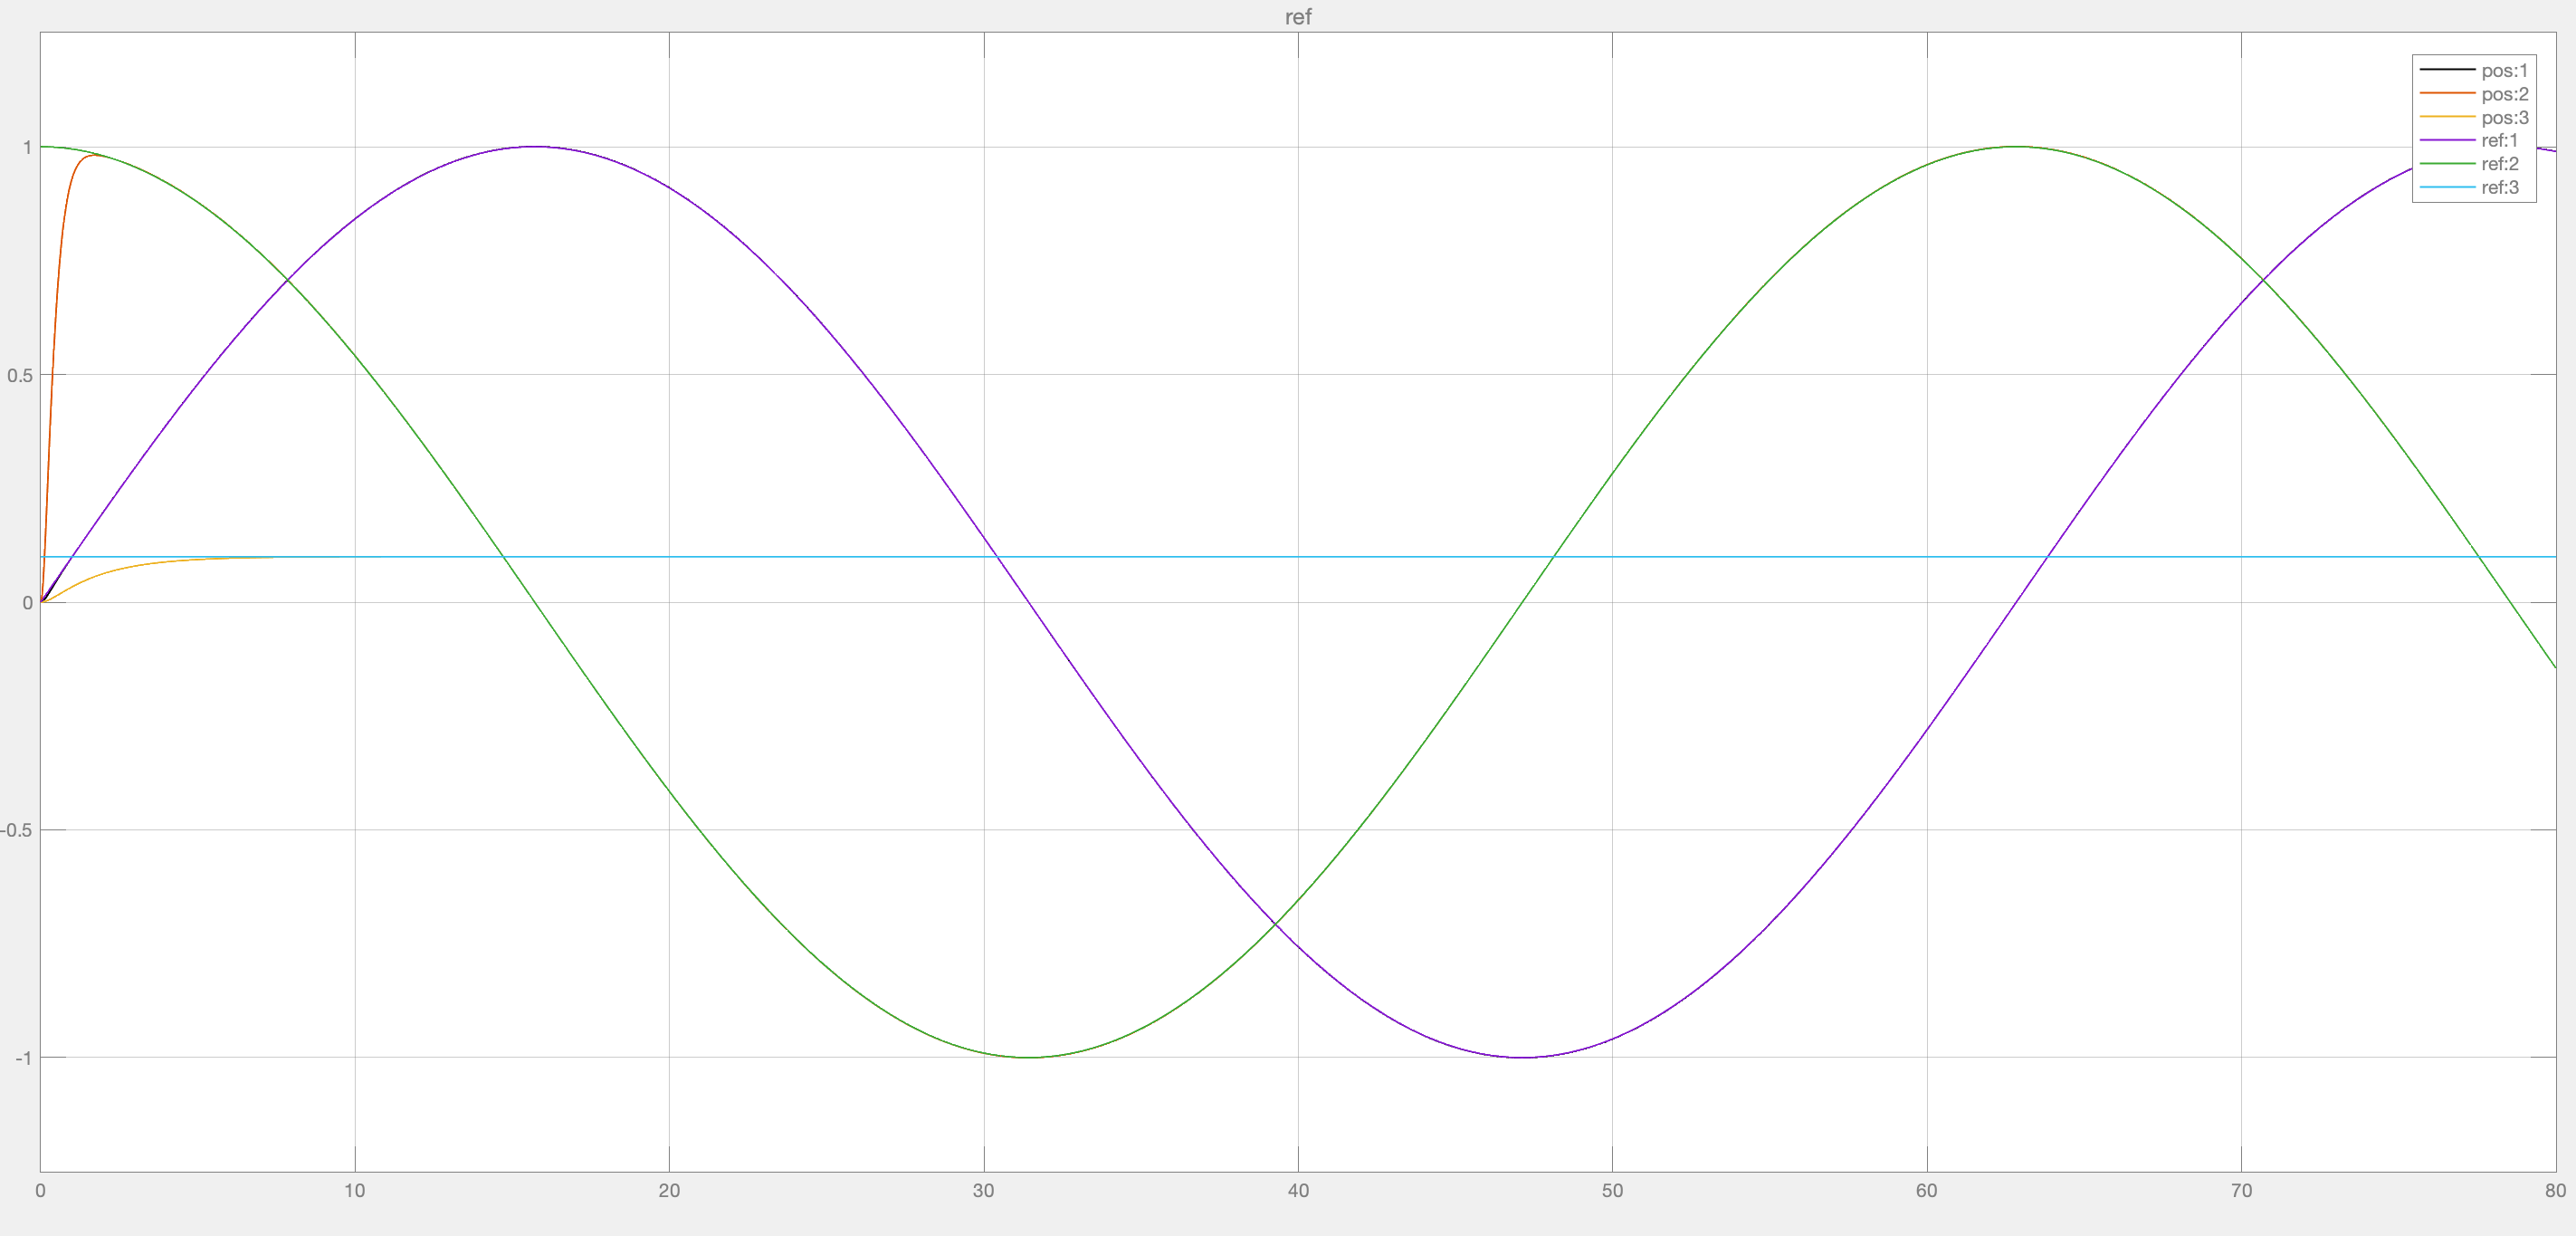

Fig k.a: pure sinusoidal with pi/2 phase shift and omega = 0.1rad/s input response

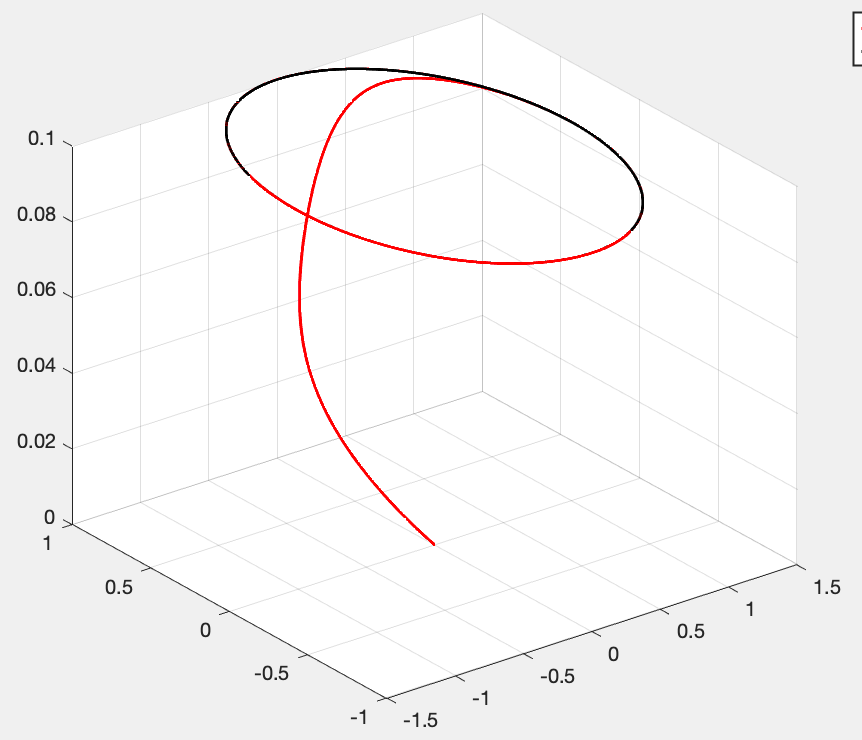

Fig k.b: plot in 3D for the pure sinusoidal input (black - reference, red - output)

As we can see from the 3D plot, even though the output tracked the reference, the plots are not in the same point for the angular motion. This is due to the case that the circular motion in the reference was started earlier while the drone is moving vertically. We can also see the effect of early angular motion tracking on the vertical motion, which is a polynomial vertical path.

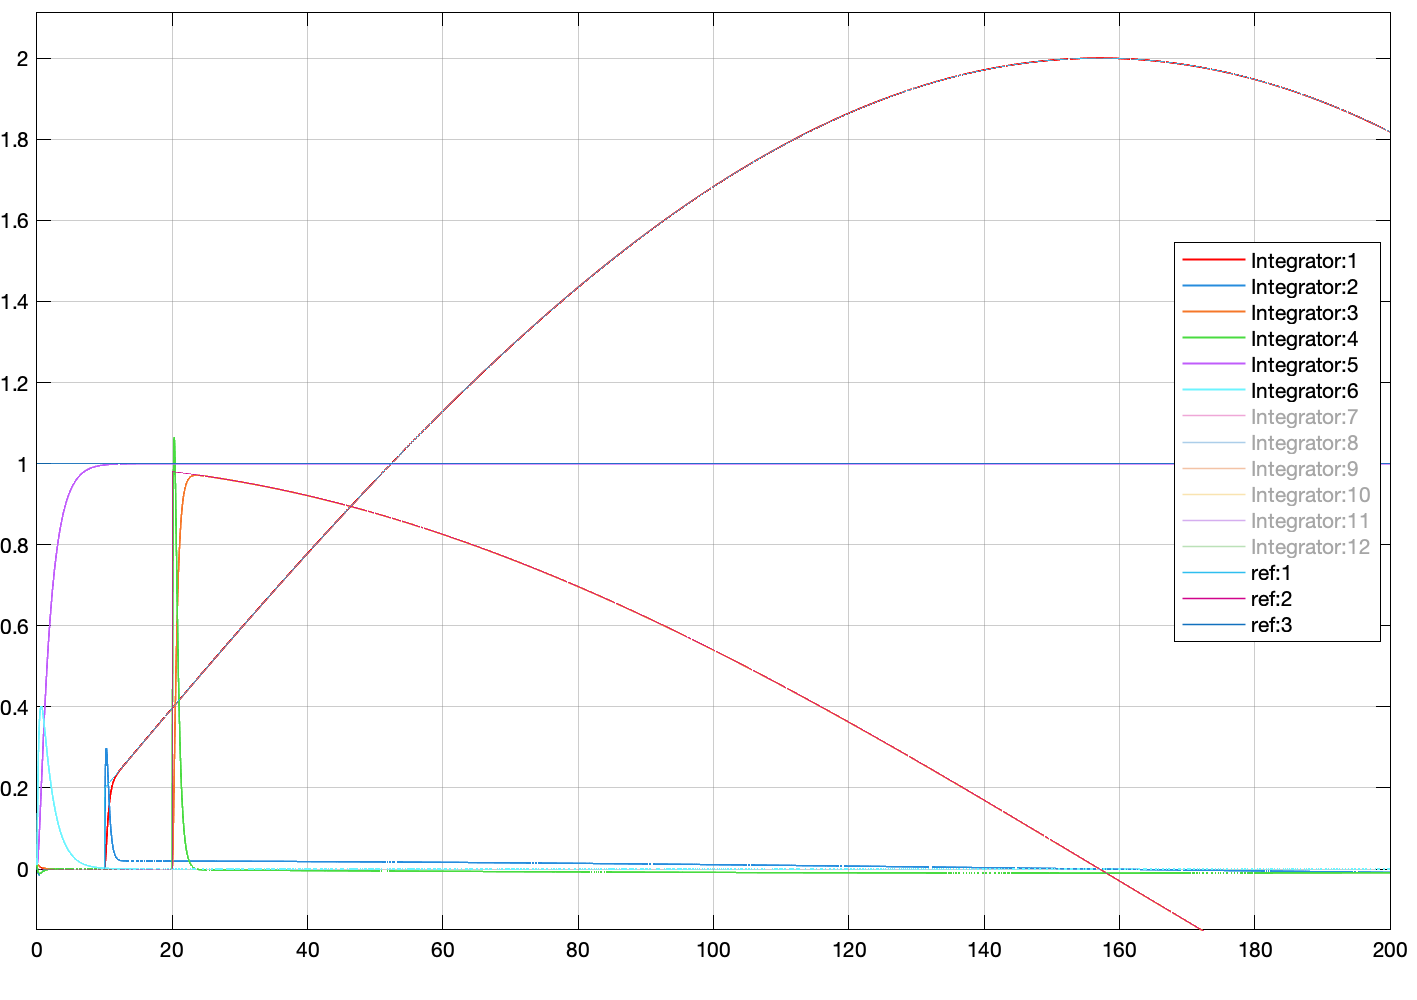

Fig k.c: variable input response at omega = 0.01rad/s

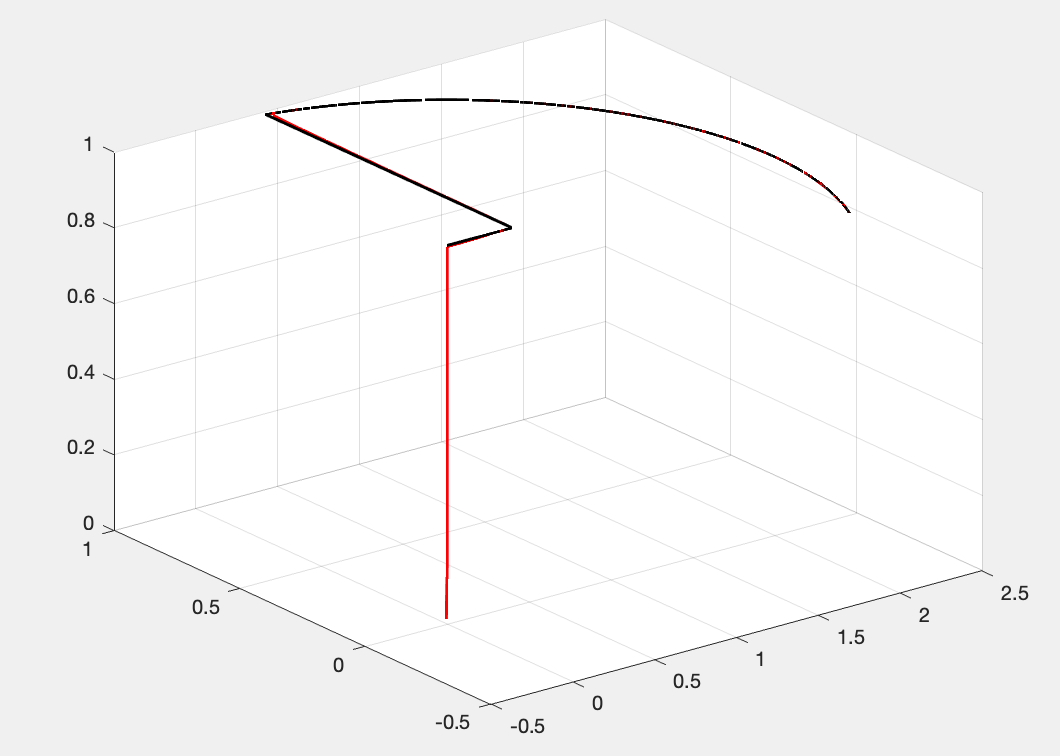

Fig k.d: plot in 3D for the pure sinusoidal input (black - reference, red - output)

The controller able to track the time varying responses efficiently and lowest error, short settling time and with no overshot.

#### 4. Compare the results with the results obtained by the linear controller

Based on the result, we can say that our controller handles the nonlinearity of the model and exactly stabilizes both the linear positions and velocities. This justifies that exact linearization method is more efficient than the approximation methods used in the previous control strategies. The previous methods has overshot when they detect sudden input changes, has higher error and settling time than exact linearization method.

# 3. Nonlinear Vertical control

 The decoupled vertical dynamics is described by:

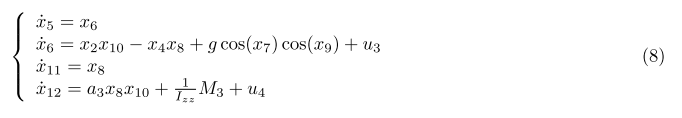

This dynamic can be decoupled into two sub-systems with dedicated controllers, the verticals displacement of the drone along the z−axis and its rotation around this axis, which is why the method of exact linearization is considered more than the other calculation methods. 

Consider the two controllers:

1. Prove that the following control inputs allows to obtain a linear closed-loop system and compute the values of k1, k2, k3 and k4 allowing to stabilize asymptotically the system.

    i. Define the system dynamics 

vertical motion


$$
\dot{x_5} = x_6 \\
\dot{x_6} = x_{10}x_2 - x_4x_8 + g \cos (x_7)\cos(x_9) + u_3 \\
\dot{x_{11}} = x_{12 }\\
\dot{x_{12}} = a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3+u_4 \\$$
            

ii. Choose an output to control

Assume that the desired output is one of the states. Let's choose **y = x_5** for vertical and **y_2 = x_8** for angular motions, which represents the the motions in z-axis.

To apply exact linearization, we need to compute the relative degree of the system with respect to **y=x_5 and y_2 = x_8**. 

Compute derivatives of **y until u_3** appears and **y_2 until u_4** appears


$$ 
\dot{y}  = \dot{x_5} = x_6 \\
\ddot{y}  = \dot{x_6} = x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7)+u_3 \\

\                                and                                        \  \\
\dot{y_2}  = \dot{x_{11}} = x_{12} \\
\ddot{y_2}  = \dot{x_{12}} = a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3+u_4
$$


Here, u_3 and u_4 appears in the second derivative of y and y_2. Hence, the relative degree of the system with respect to **y = x_3 and y_2 = x_8** is 2. 

iii. **Linearize the system (Feedback Linearization)**

The general form for the second-order system is: **ddy = v, and ddy_2 = v_2** where **v and v_2** are new (fictitious) control inputs.

**Now lets define the control law for ****u_3 and u_4**

We can rewrite the equations as:

$ 
\ddot{y}  = v, \ then \\
u_3 = v - (x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7))
$     ;    $ 
\ddot{y}_2  = v_2, \ then \\
u_4 = v_2 - (a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3)
$

This control law effectively cancels the nonlinearities in the system, transforming the system into **ddy = v and ddy = v_2**.

iv. **Control design for v and v_2**

We now design **v and v_2 to make y and y_2 **track a desired trajectory **y_desired and y_2_desired**.

Lets substitute the control inputs in the original equations:


$$ 
\dot{y}  = \dot{x_5} = x_6 \\
\ddot{y}  = \dot{x_6} = x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7)+(v - (x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7))) \\

\                                and                                        \  \\
\dot{y_2}  = \dot{x_{11}} = x_{12} \\
\ddot{y_2}  = \dot{x_{12}} = a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3+(v_2 - (a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3))
$$


Then, from feedback rule v = -Kx, and  the reduced version will be:

$ 
\dot{x_5} = x_6 \\
\dot{x_6} = v   \      --->  \          v = -Kx \\

\                                and                                        \  \\
\dot{x_{11}} = x_{12} \\
\dot{x_{12}} = v_2    \  --->   \   v_2 = -K_2x$     ===>             $ 
\dot{x_5} = x_6 \\
\dot{x_6} =  -k_1 x_5 - k_2 x_6 ;      \ where \ K = [k_1 \ k_2] \\

\                                and                                        \  \\
\dot{x_{11}} = x_{12} \\
\dot{x_{12}}  = -k_3 x_{11} - k_4 x_{12}.  ;     \ where \ K_2 = [k_3 \ k_4]$

In matrix form, we can write it like below:

$\dot{x} = Ax$   == >    $\left\lbrack \begin{array}{c}
\dot{x_5 } \\
\dot{x_6 } \\
\dot{x_{11} } \\
\dot{x_{12} } 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-k_1  & -k_2  & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & -k_3  & -k_4 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_5 \\
x_6 \\
x_{11} \\
x_{12} 
\end{array}\right\rbrack$

We can also rewrite A into sub-matrices

A = $\left\lbrack \begin{array}{cc}
A_1  & 0\\
0 & A_2 
\end{array}\right\rbrack$ ==> A1 = $\left\lbrack \begin{array}{cc}
0 & 1\\
-k_1  & {-k}_2 
\end{array}\right\rbrack$ and A2 = $\left\lbrack \begin{array}{cc}
0 & 1\\
-k_3  & {-k}_4 
\end{array}\right\rbrack$

From the representation its observed that we can compute $K=\;\left\lbrack \begin{array}{cccc}
k_1  & k_2  & k_3  & k_4 
\end{array}\right\rbrack$, by using characteristic equation of eigenvector $\det \left(\lambda I-A\right)=0$, where $\lambda$ is the eigenvalue of A , and we can write A = $\left\lbrack \begin{array}{cc}
A_1  & 0\\
0 & A_2 
\end{array}\right\rbrack$ so, the characteristic equation will be $\det \left(\lambda I-A\right)*$$\det \left(\lambda I-A\right)=0$. Now, we can solve for K values by selecting the desired eigen vectors that make the system stable; by default poles in LHS region.

syms k1 k2 k3 k4

$$eqn = \left(4\,k_{2}-4\,k_{1}+4\right)\,\left(3\,k_{4}-6\,k_{3}+3\right)$$

A1 = [0 1; -k1 -k2];
A2 = [0 1; -k3 -k4];
lam1 = [-4, -3]; 
lam2 = [-3, -5];
eqn = det(lam1*eye(2)-A1)*det(lam2*eye(2)-A2)

Here, we can see that 

k2 = k1 - 1     and k4 = 2*k3 -1

if we choose k1 = 4 and k3 = 6, then k2 = 1 and k4 = 7

Then,


$$u_3 = -k_1x_5 - k_2x_6 - (x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7))   \\
u_4 = -k_3x_{11} -k_4x_{12}- (a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3) ; \ \frac{1}{I_{zz}}M_3 = u_5
$$


numerically,


$$u_3 = -4x_5 - x_6 - (x_{10}x_2-x_4x_8 + g\cos(x_9)\cos(x_7))   \\
u_4 = -6x_{11} -7x_{12}- (a_3x_{10}x_8 + \frac{1}{I_{zz}}M_3) ;
$$


2. Simulate the vertical model with a 0-reference z position and a non-zero constant and positive position (Hovering flight).

Fig l.a: response at zero reference in rx=ry=rz=0;

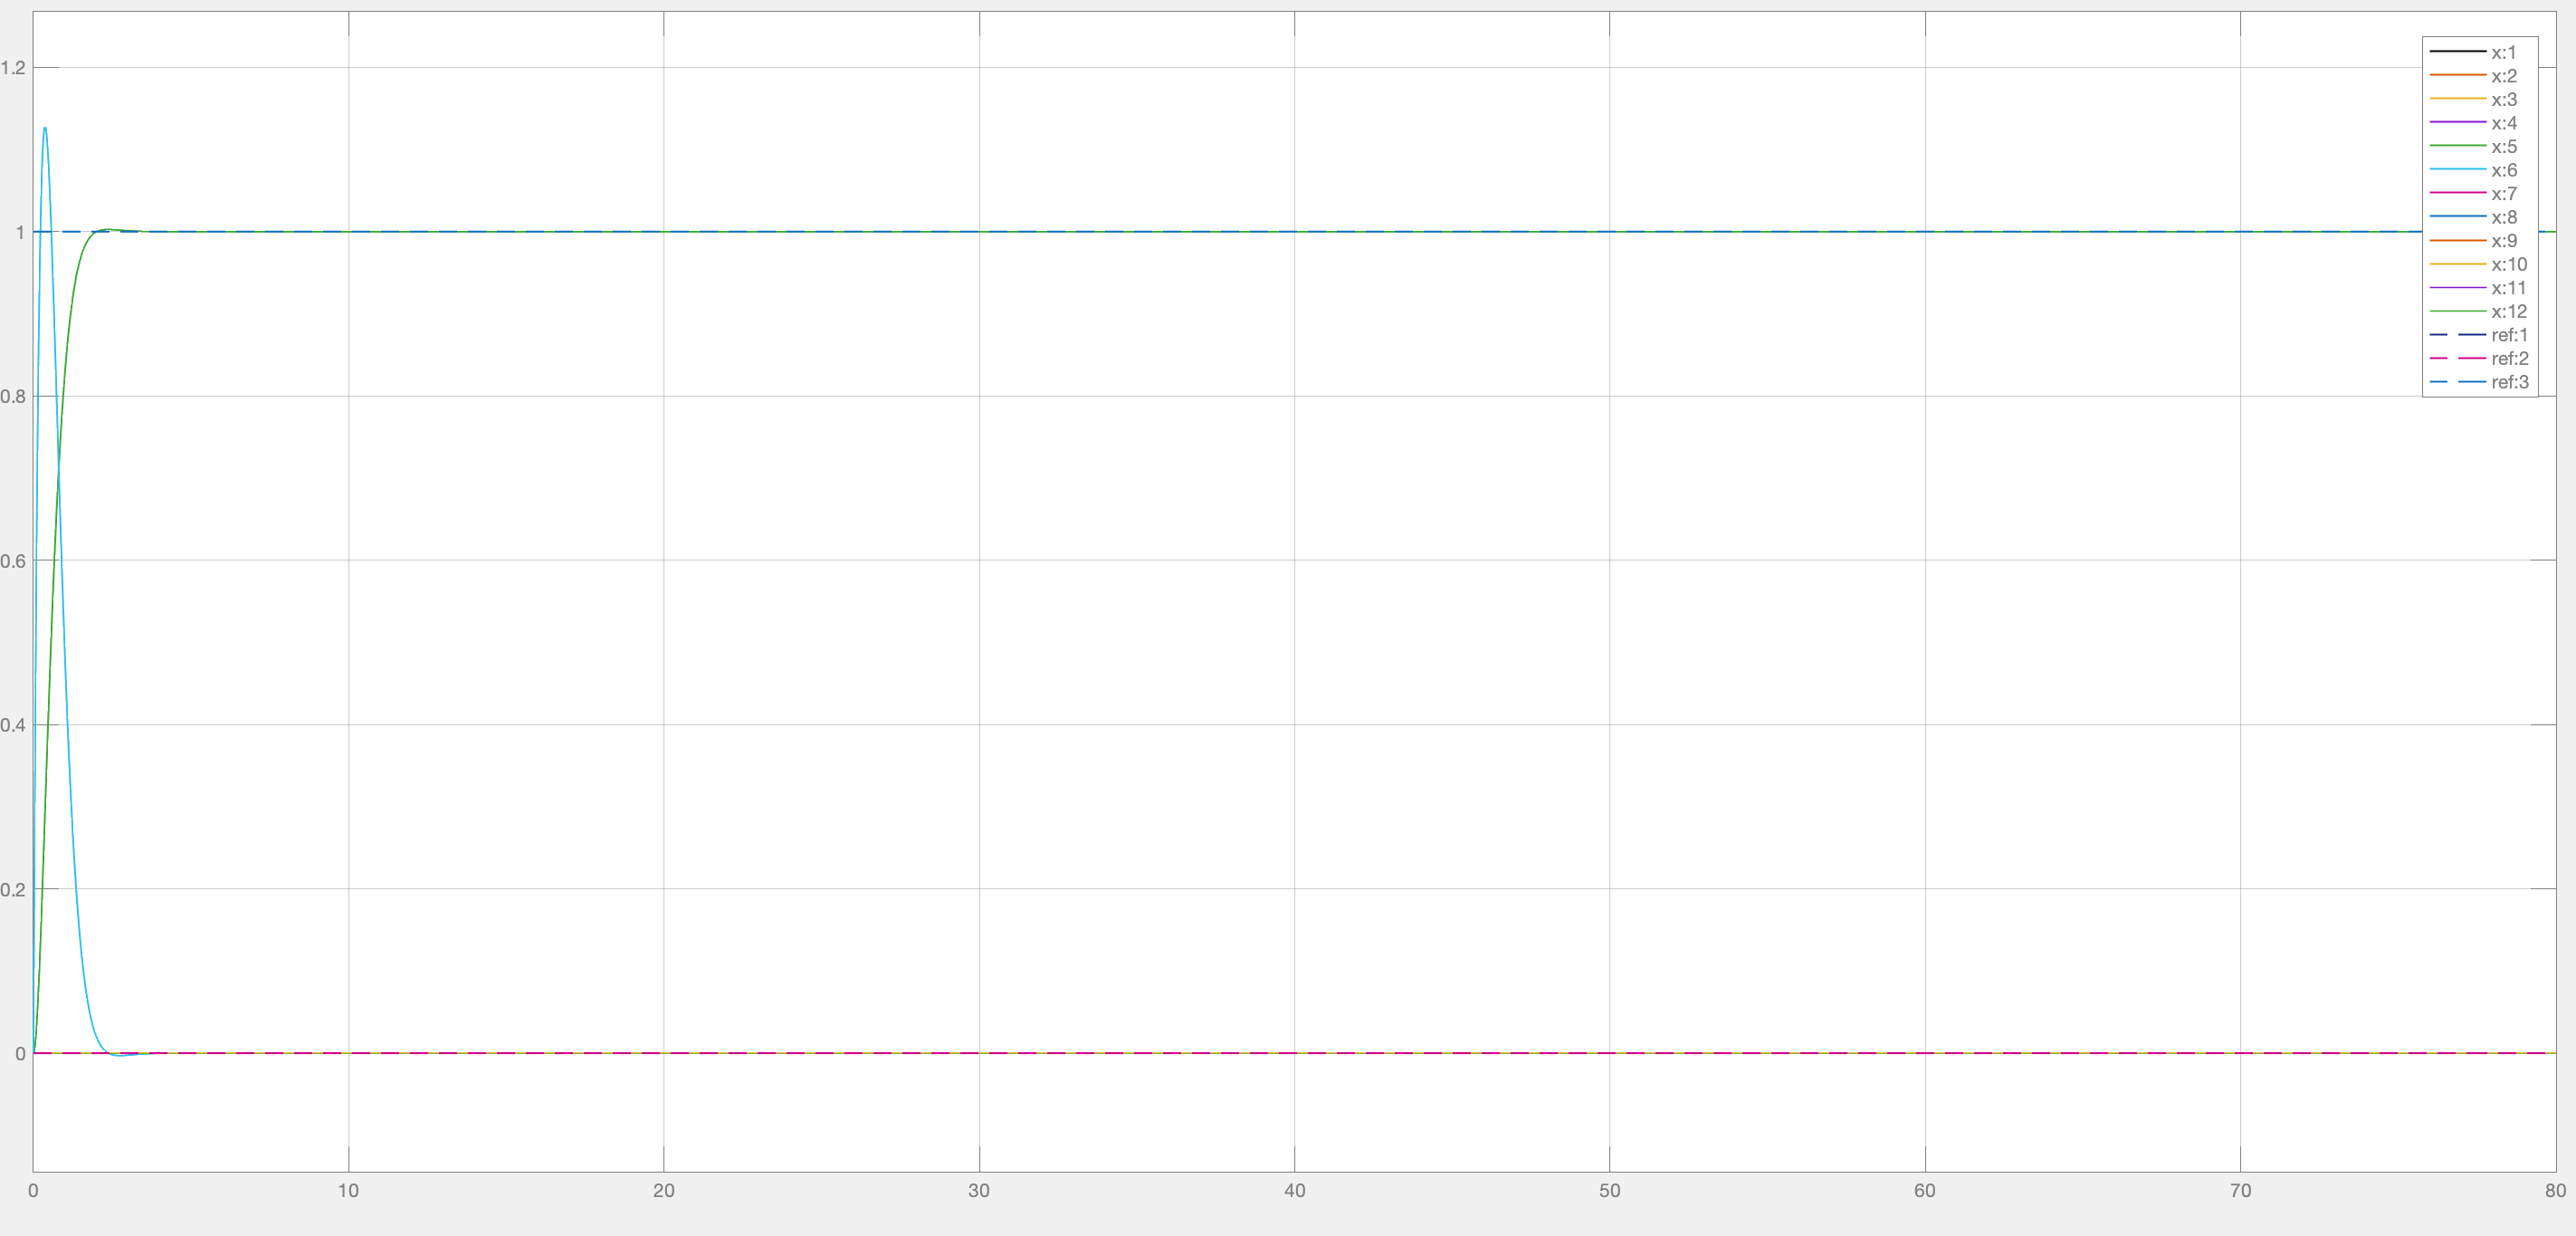

Fig l.b: response at non-zero constant reference in rx=ry=0; rz=1;

Based on the result, the designed controller perfectly controlled the vertical linear and angular motions for zero and constant reference inputs. The controller designed using exact linearization gave us a promising result. At constant reference of rz=1, the motion in z-axis (vertical) and all other responses stayed at zero. The settling time is also very small and there is no overshot for the vertical position.

# 4. Autonomous control of the complete system 

In this section, the previous controllers will be applied to the complete model. 

1. Simulate the closed loop system with a setpoint in zero position. 

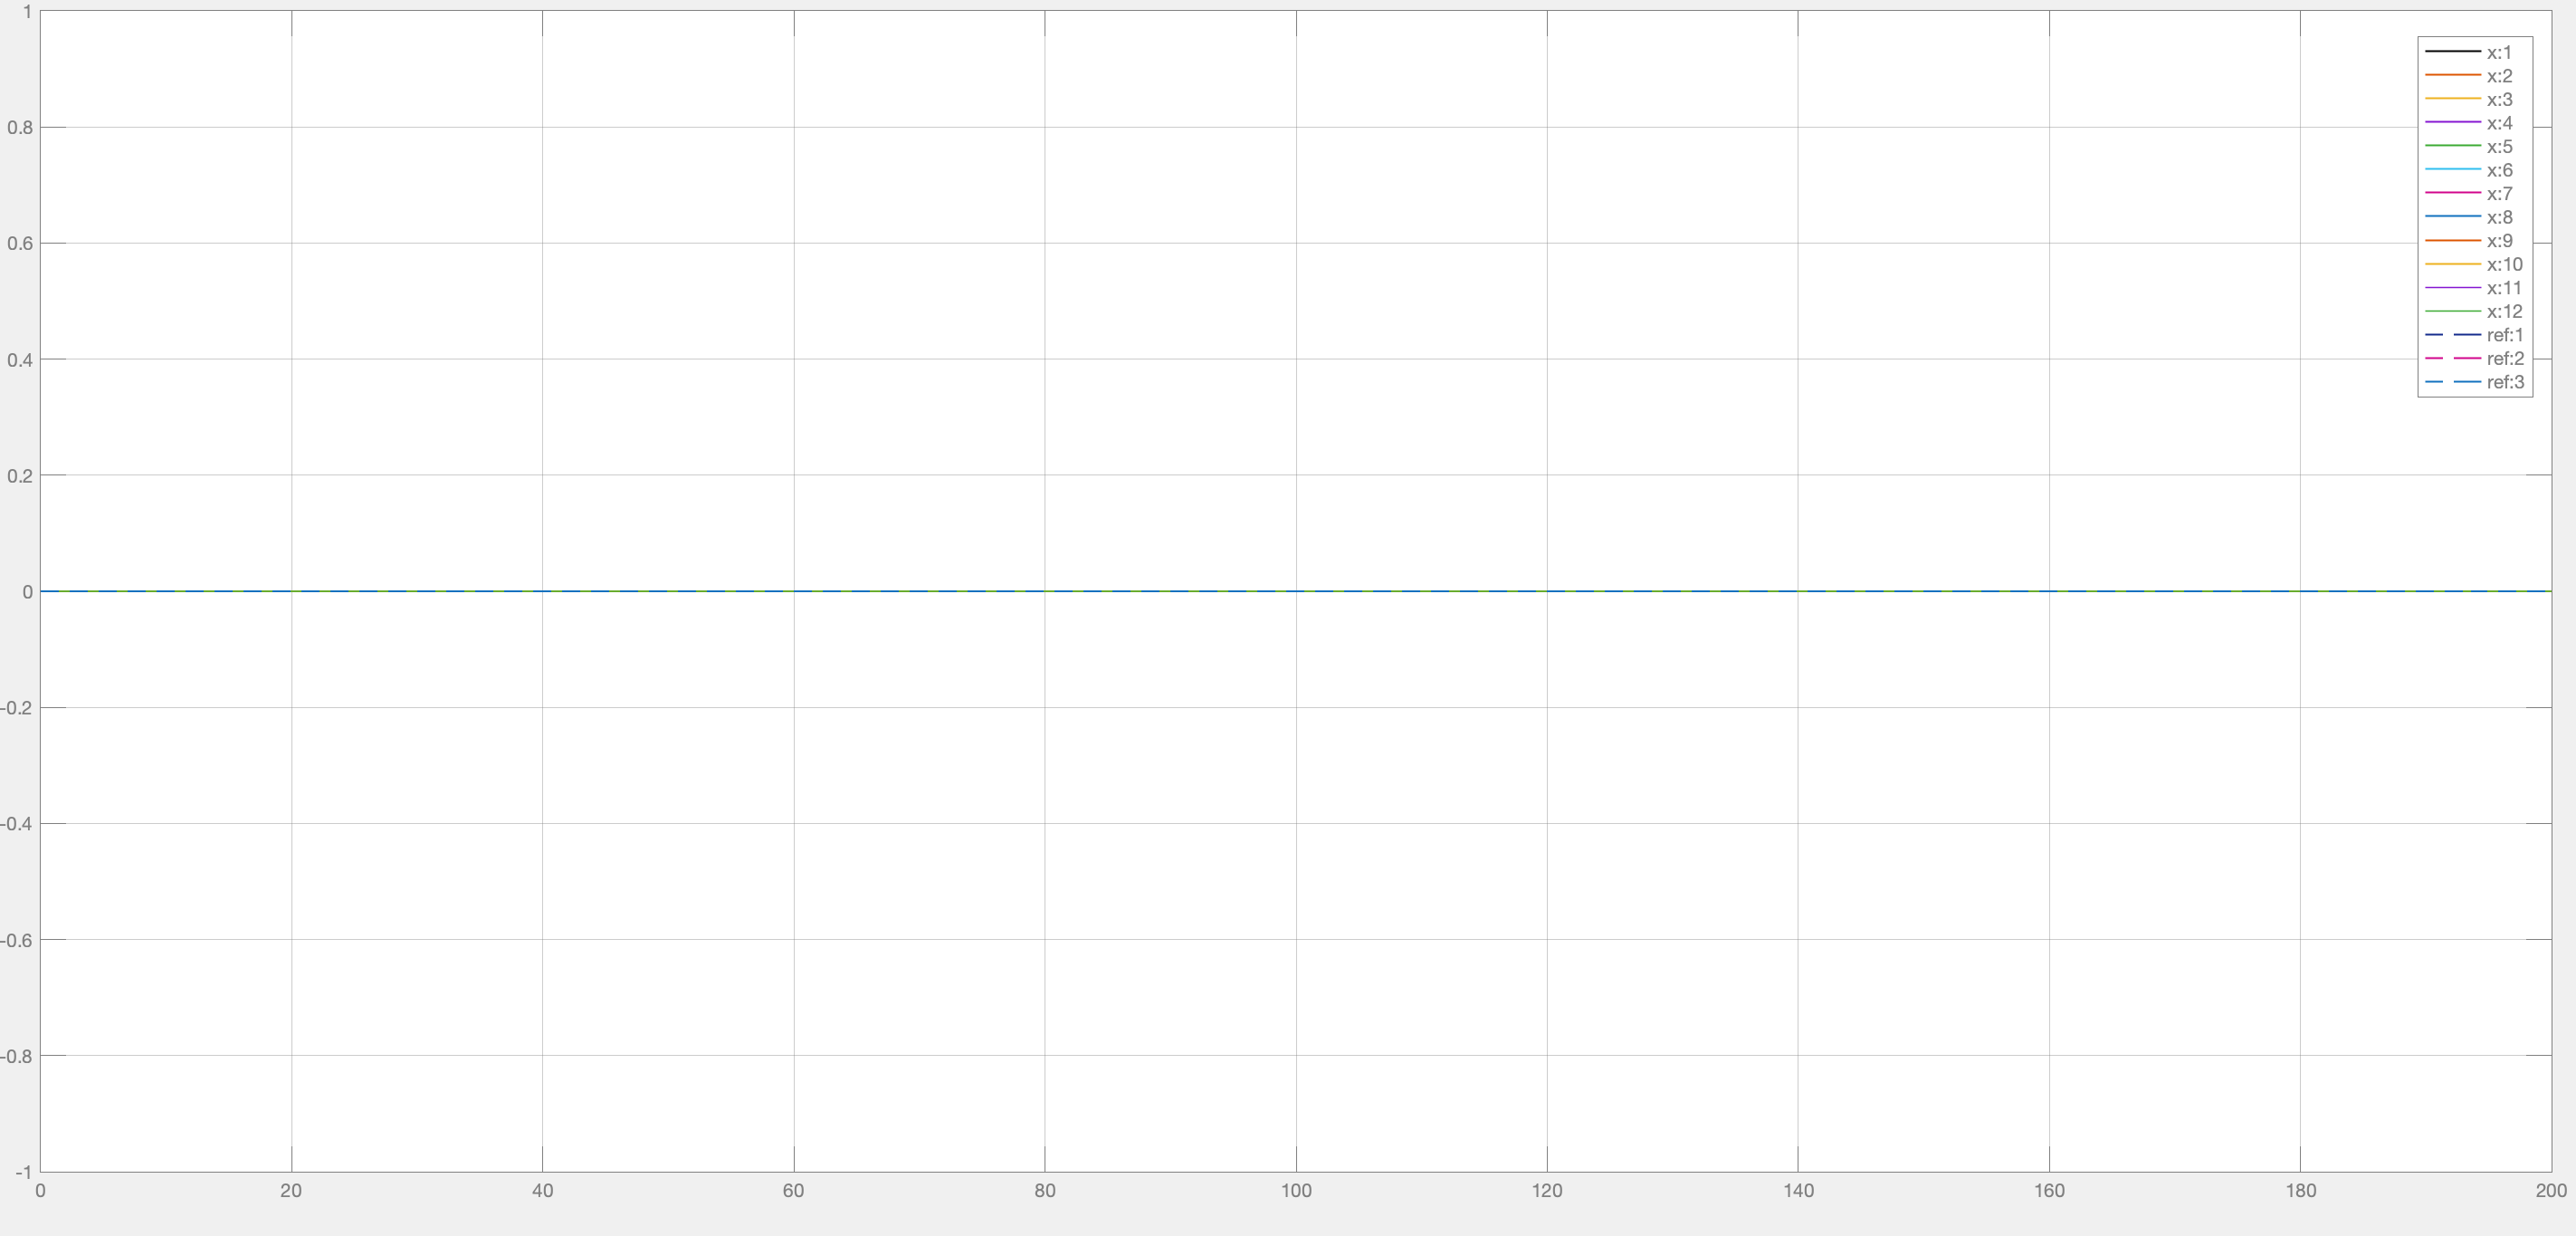

From the zero reference input response, we observed that the system is stable at the origin and nearby points. While the exact linearization is expected to track at any points, but it has some spikes at the transient state.

2. Simulate the closed loop system with a reference trajectory: 

        (a) Vertical and hovering flights at 1m 

        (b) At 10s longitudinal flight 1m 

        (c) At 20s lateral flight 1m

        (d) At 40s landing.

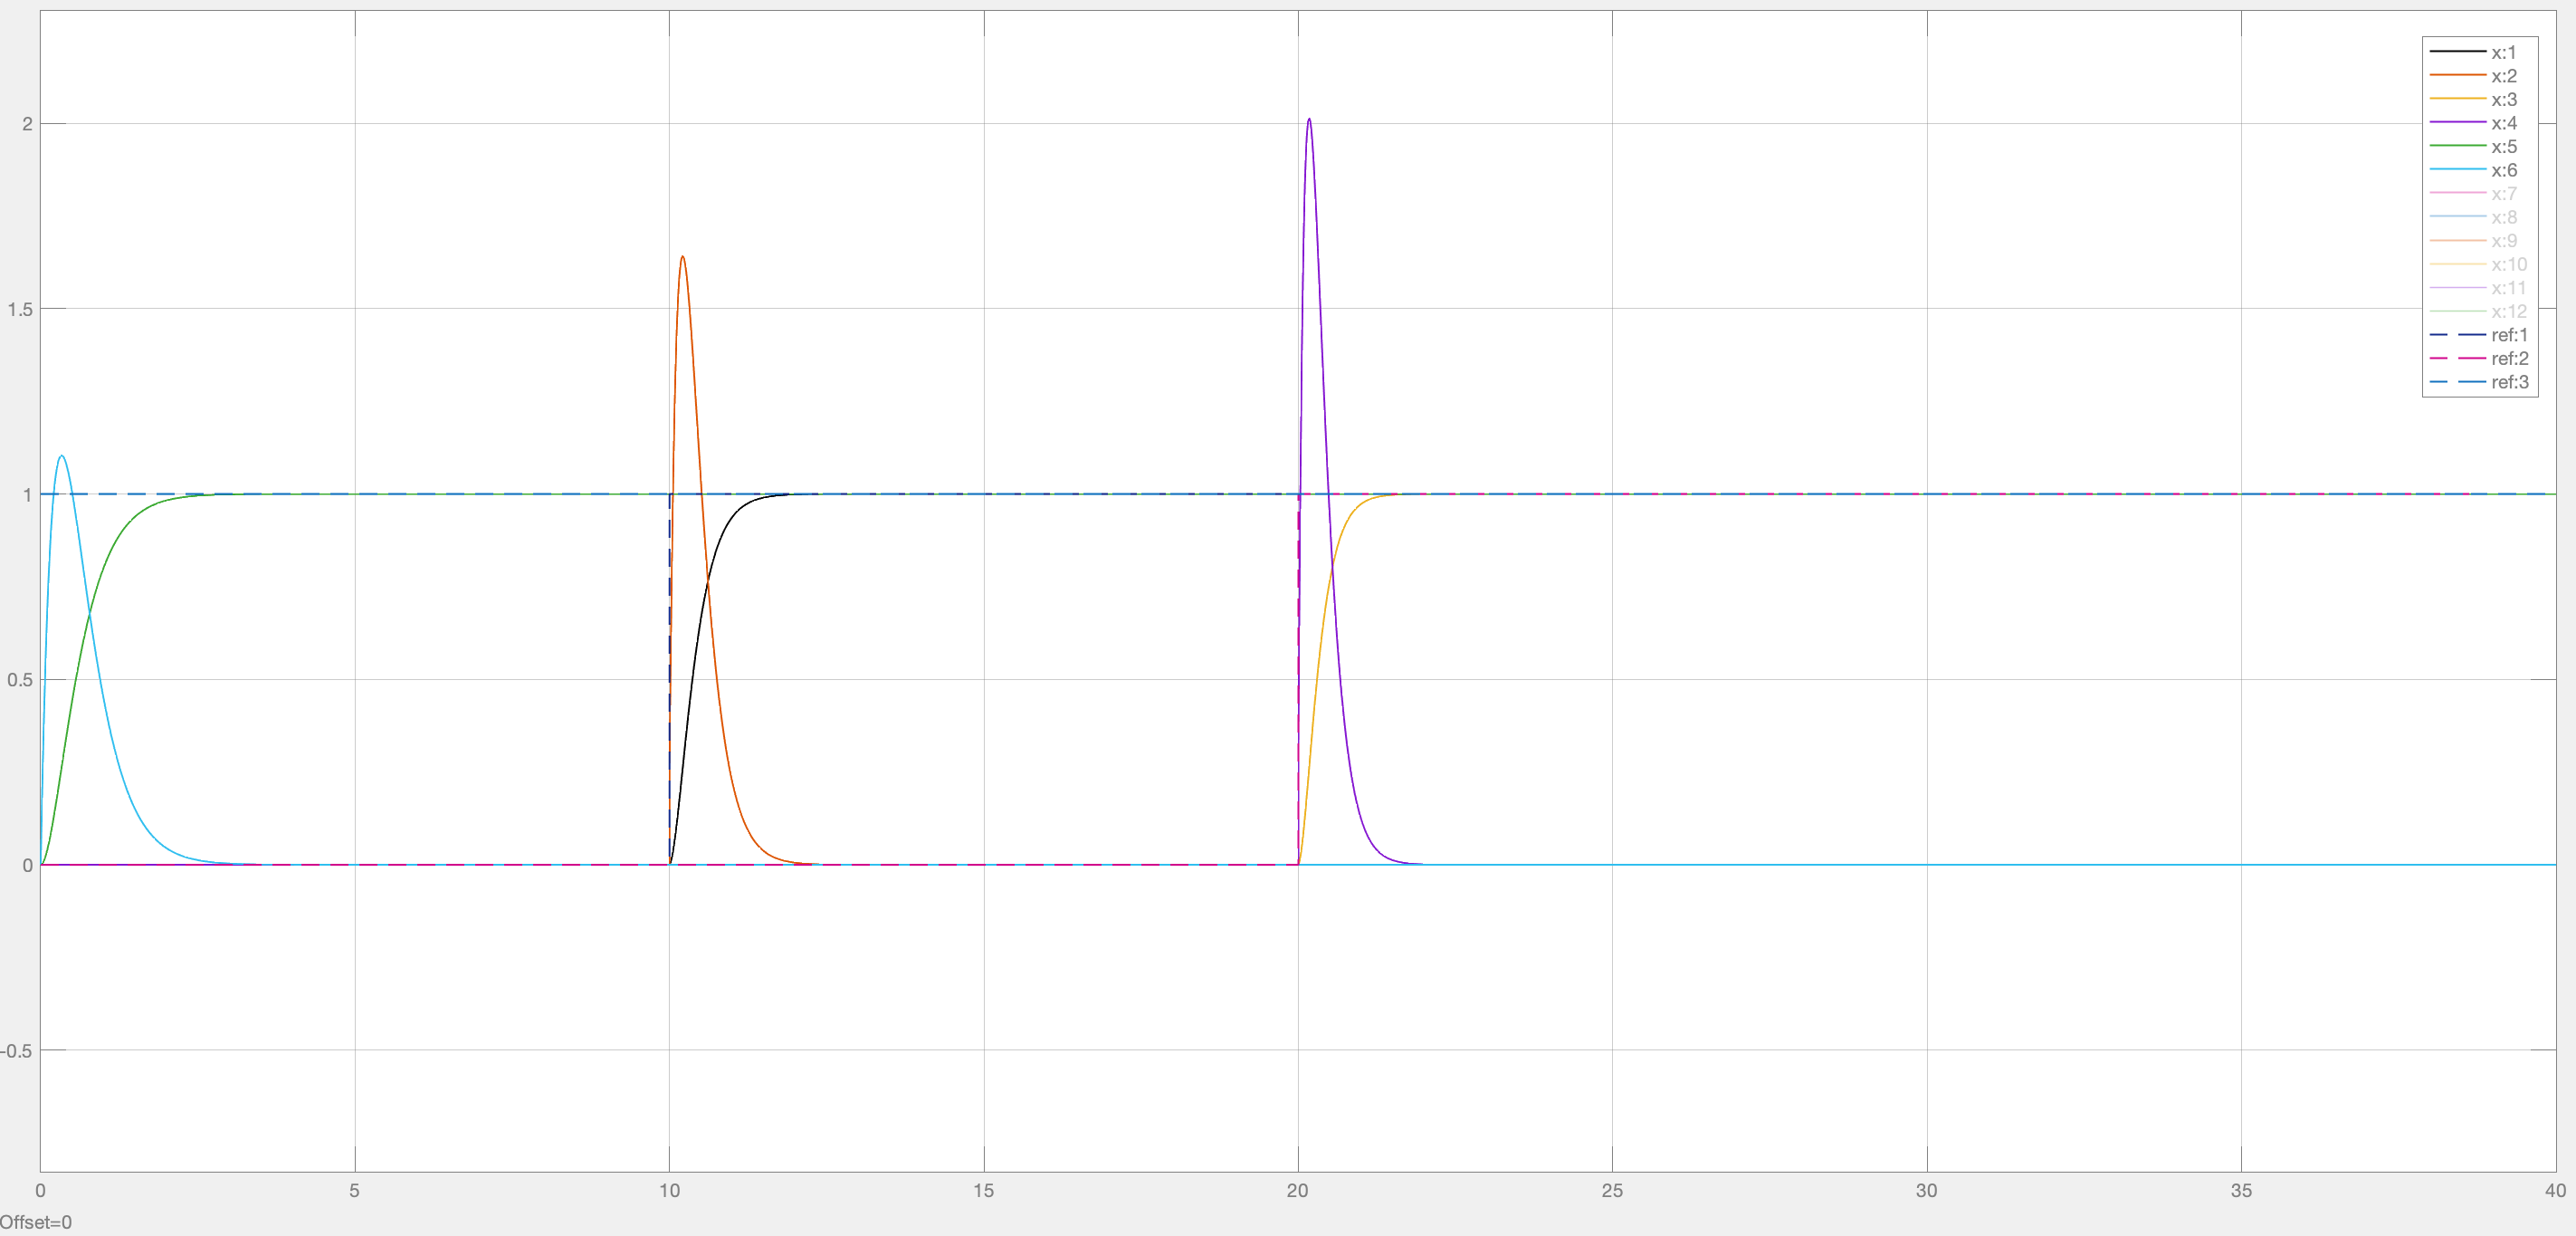

Fig l.c: combined response for constant reference inputs given above

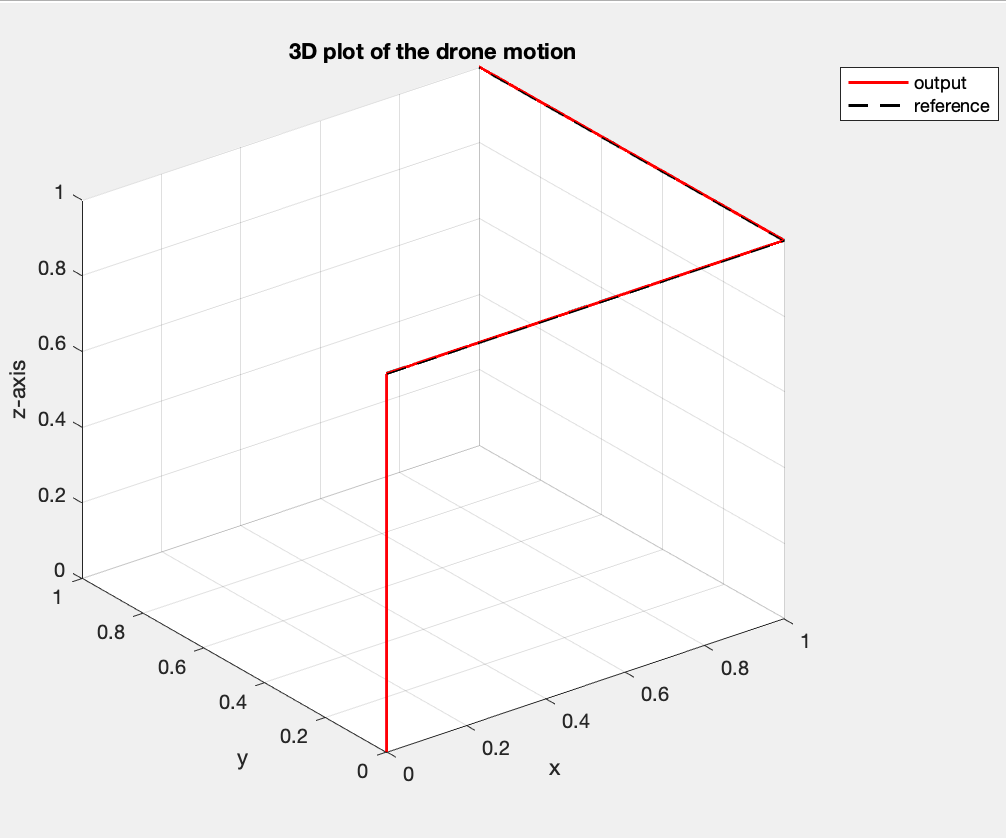

Fig l.d: 3D plot of the drone motion at constant trajectory

In a constant trajectory, the drone moved in each direction independently. First the drone moved upward, then horizontally in the x-axis and laterally in the y-axis. after moving in these directions, the drone will stay in the hovering state till a change in input is applied. In constant trajectory tracking, the positions of the drone tracked the reference in a short period of time.

3. Simulate the closed loop system with : 

        (a) Vertical and hovering flights at 1m 

        (b) Circle flight in the x − y plan

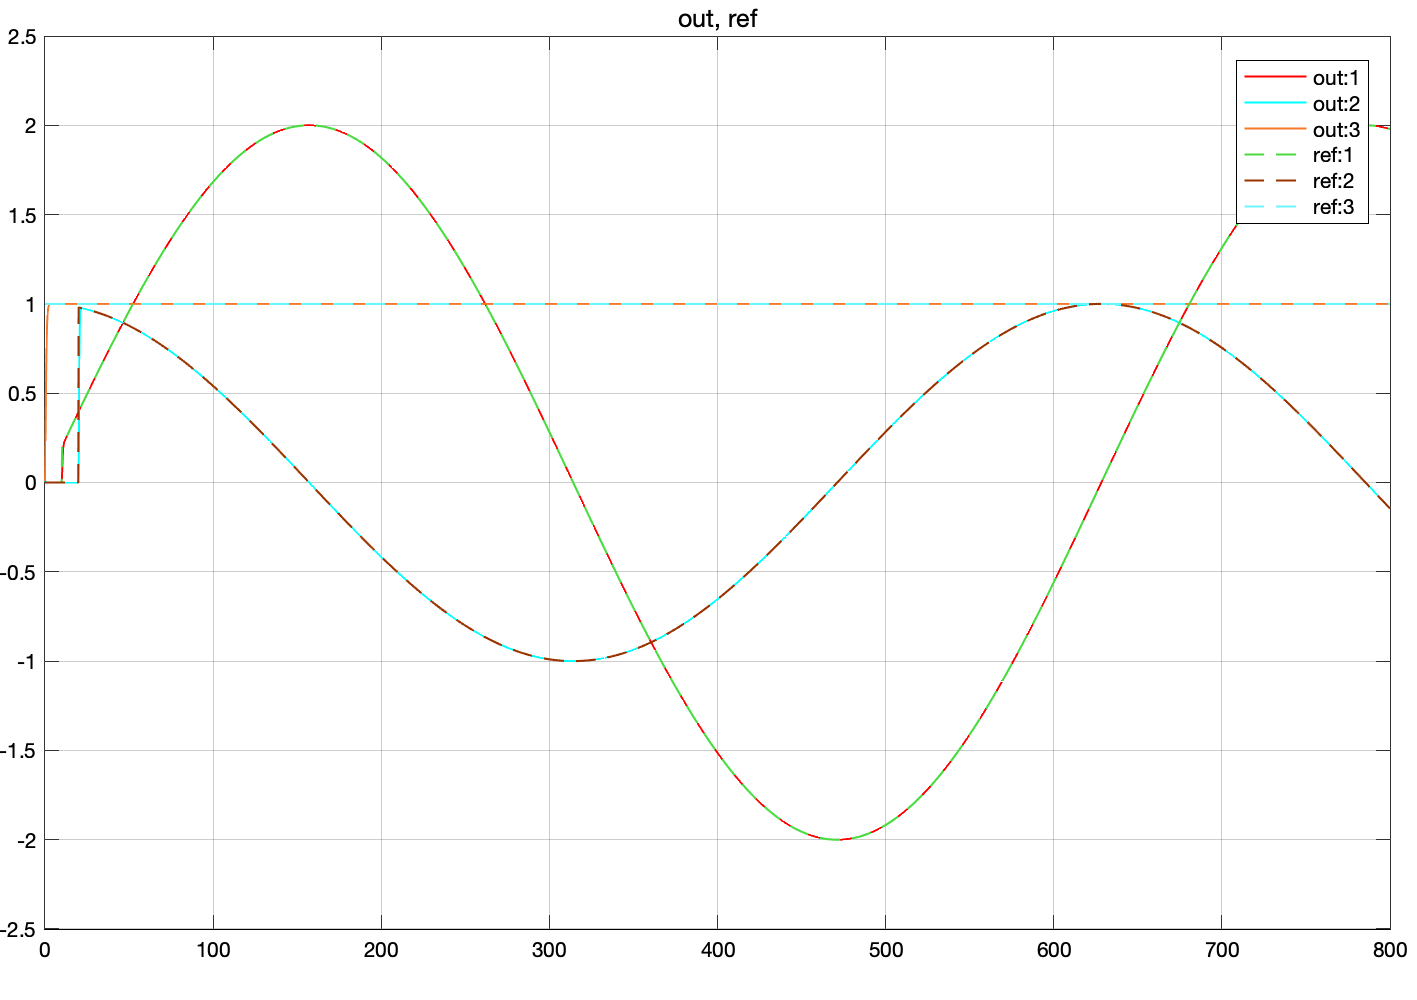

Fig m.a: time varying reference tracking

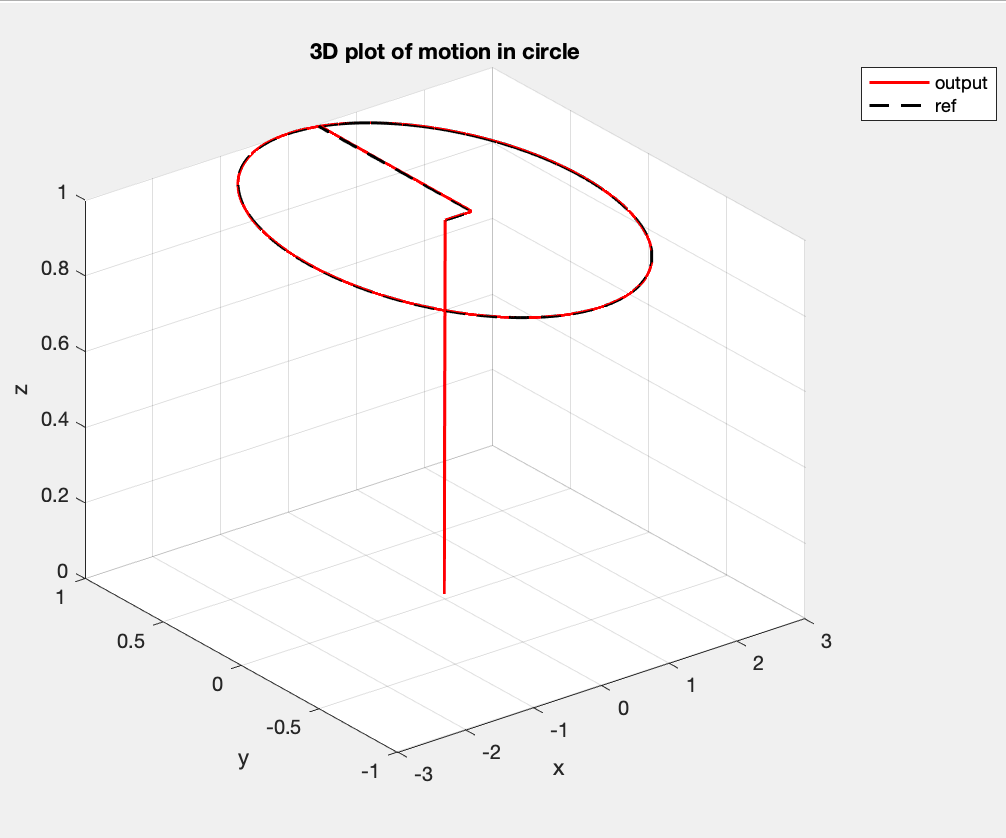

Fig m.b: 3D plot of the circular motion

The controller designed using exact linearization was able to track the circle trajectory perfectly. This justified that what ever the reference trajectory, the controller has a capability to control the drone motion. 

# Summary

This lab report presents the analysis, design, and implementation of flight modeling and control strategies using Pole Placement, Linear Quadratic Regulator (LQR), and Exact Linearization techniques. The objective was to develop control systems capable of achieving stability, robustness, and optimal performance for a given flight dynamics model. The Pole Placement method was employed to position the system's poles in desired locations within the complex plane, ensuring specific dynamic response characteristics. The LQR approach was utilized to achieve optimal control by minimizing a quadratic cost function, balancing control effort with system performance. Lastly, the Exact Linearization technique was applied to transform the nonlinear flight dynamics into a linear form, facilitating the design of effective control laws. Each method's performance was evaluated through simulation, with comparisons made in terms of response time, stability margins, and control effort. The results highlight the strengths and limitations of each approach, providing insights into their applicability for modern flight control systems.

Challenges of Each Control Method

**Pole Placement**

- Sensitivity to Model Uncertainty: Pole placement relies heavily on an accurate model of the system. Small modeling errors can result in poor control performance or instability.

- Design Complexity: Selecting appropriate pole locations to achieve a balance between system speed, stability, and overshoot can be challenging, especially for higher-order or multivariable systems.

- Limited Optimality: Unlike LQR, pole placement does not explicitly minimize a cost function, making it less efficient in terms of control effort.

**Linear Quadratic Regulator (LQR)**

- Tuning the Cost Function: Determining the weight matrices QQ (state cost) and RR (control cost) is non-trivial and often requires trial and error or heuristic methods.

- Full State Feedback Requirement: LQR assumes full state observability, which may not be practical in real systems where only a subset of states is measurable, requiring state estimation or observers.

- Computational Burden: While LQR is efficient for offline design, real-time applications may face computational challenges, especially for large systems with high dimensionality.

**Exact Linearization**

- Nonlinearity and Complexity: Exact linearization requires precise knowledge of the nonlinear dynamics and can become extremely complex for systems with strong nonlinearities.

- Model Dependence: Since the method linearizes around a trajectory or an operating point, deviations from this point (like large disturbances) can reduce control effectiveness.

- Implementation Difficulty: The transformation to a linearised form may introduce control complexities that are difficult to implement in real-time systems.

In sum up, LQR is recommended for its balance of optimality, robustness, and ease of implementation. However, each method has its own strengths and challenges, and the final choice may depend on the specific flight control application, system constraints, and operational requirements. Such as the exact linearization method has better performance and very low error, however it is not cost effective, and the design process is too complex.

# Appendix

Controller code

function u = fcn(x,rx,ry,rz, K2, K1) % V_mat1, V_mat2,
%#codegen



u = zeros(6,1);

g  = 9.81;

% les moments inirtiels
Ixx=7.5*10^-3;
Iyy=7.5*10^-3;
Izz=1.3*10^-3;

k1 = 2; k2 = 3;
k3 = 3; k4 = 5;
k5 = 9; k6 = 6;
k7 = 2; k8 = 3;
k9 = 2; k10 = 6;
k11 = 2; k12 = 3;

% les coeficients
a1=((Iyy-Izz)/Ixx);
a2=((Izz-Ixx)/Iyy);
a3=((Ixx-Iyy)/Izz);

% % LQR + pole placement method
% % longitudinal
% xlong = [x(1); x(2); x(9); x(10)];
% u(1) = -K1*xlong+V_mat1(1)*rx(1); % To be completed;
%
% % lateral
% xlat = [x(3); x(4); x(7); x(8)];
% u(2) = -K2*xlat + V_mat2(1)*ry(1); % To be completed;


% u(3) = -(x(10)*x(2)-x(8)*x(4)+g*cos(x(7))*cos(x(9)))-k5*(x(5)-rz)-k6*x(6);
% u(4) = -(a1*x(12)*x(10))-k7*x(7)-k8*x(8);
%

% exact linearization
% longitudinal control
u(1) = K1(1)*(rx(1)-x(1))+K1(2)*(rx(2)-x(2))-(x(12)*x(4)-x(10)*x(6)-g*sin(x(9)));

% lateral control

u(2) = K2(1)*(ry(1)-x(3))+K2(2)*(ry(2)-x(4))-(x(8)*x(6)-x(12)*x(2)+g*sin(x(7))*cos(x(9)));

u(3) = -k5*(x(5)-rz)-k6*x(6)-(x(10)*x(2)-x(4)*x(8)+g*cos(x(9))*cos(x(7)));
u(4) = -k7*x(11)-k8*x(12)-a3*x(10)*x(8);


u(5) = -a2*x(12)*x(8)-k9*x(9)-k10*x(10);

% u(6) = -k11*x(7)-k12*x(8)-a1*x(12)*x(10);
end

Model/ plant code

function dx = fcn(x,u)
%#codegen

g  = 9.81;

% les moments inirtiels
Ixx=7.5*10^-3;
Iyy=7.5*10^-3;
Izz=1.3*10^-3;


% les coeficients
a1=((Iyy-Izz)/Ixx);
a2=((Izz-Ixx)/Iyy);
a3=((Ixx-Iyy)/Izz);

dx = zeros(12,1);

dx(1) = x(2);
dx(2) = x(12)*x(4)-x(10)*x(6)-g*sin(x(9))+u(1);
dx(3) = x(4);
dx(4) = x(8)*x(6)-x(12)*x(2)+g*sin(x(7))*cos(x(9))+u(2);
dx(5) = x(6);
dx(6) = x(10)*x(2)-x(8)*x(4)+g*cos(x(7))*cos(x(9))+u(3);
dx(7) = x(8);
dx(8) = a1*x(12)*x(10)+u(2);
dx(9) = x(10);
dx(10) = a2*x(12)*x(8)+u(1);
dx(11) = x(12);
dx(12) = a3*x(8)*x(10)+u(4)+u(5);

end